# Neuron data-inator

## Import

cd Documents/Datos_monos_32y33/RR033_processed/All_Neurons

VPCd 32

N = 264; %number of neurons
P = 17; %number of psychometrics files

Psychos = cell(N,1);
Neurons = cell(N,1);

n = 1; p = 1;
Files=dir('*.*');
for f = 1:length(Files)
    if length(Files(f).name) > 3 && Files(f).name(8) == "e"
        Neurons{n} = readmatrix(Files(f).name);
        n = n + 1;
    elseif Files(f).name(1) == "p"
        Psychos{p} = readPsico(Files(f).name);
        p = p + 1;
    end
end

pi = AllPsico;

VPCi 32

N = 310; %number of neurons
P = 20; %number of psychometrics files

Psychos = cell(N,1);
Neurons = cell(N,1);

n = 1; p = 1;
Files=dir('*.*');
for f = 1:length(Files)
    if length(Files(f).name) > 3 && Files(f).name(8) == "e"
        Neurons{n} = readmatrix(Files(f).name);
        n = n + 1;
    elseif Files(f).name(1) == "p"
        Psychos{p} = readPsico(Files(f).name);
        p = p + 1;
    end
end

pi = AllPsico;

VPCd 33

N = 345; %number of neurons
P = 23; %number of psychometrics files

Psychos = cell(N,1);
Neurons = cell(N,1);

n = 1; p = 1;
Files=dir('*.*');
for f = 1:length(Files)
    if length(Files(f).name) > 3 && Files(f).name(8) == "e"
        Neurons{n} = readmatrix(Files(f).name);
        n = n + 1;
    elseif Files(f).name(1) == "p"
        Psychos{p} = readPsico(Files(f).name);
        p = p + 1;
    end
end

pi = AllPsico;

### RNN

N = 256;
E = 400; 

Fr = cell(N,1);
for n = 1:N
    neurona = [E*(n-1)+1:E*n];
    Fr{n} = BDneu(neurona,:);
end

Psyhit = cell(1,1);
Psyhit{1} = BDinfoT4;
pi = ones(1,N);

### All

N = 919;
P = 68;
Fr = [Frd32;Fri32;Frd33]; 
Psyhit = [Psyhitd32;Psyhiti32;Psyhitd33];
pi = [pid32;pii32;pid33];
pi(265:end) = pi(265:end) + 17;
pi(575:end) = pi(575:end) + 20;

FInd t minimum 

m = 0;
for n = 1:N
    if min(Neurons{n}, [], "all") < m
        m = min(Neurons{n}, [], "all");
    end
end
m

### Remove misses and fix neurons VPCd 32

Neu = cell(N,1); Psyhit = cell(N,1);
for n = 1:N
    if pi(n) == 1
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial < 145, :);
        Psyhit{1} = Psychos{1}(Psychos{1}.Hits == 1 & Psychos{pi(n)}.Trial < 145, :);
    else
        try
            Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1, :); 
        catch
            n
        end
    end
end

for p = 2:P
    Psyhit{p} = Psychos{p}(Psychos{p}.Hits == 1, :); 
end

### Remove misses and fix neurons VPCi 32

Neu = cell(N,1); Psyhit = cell(P,1);
for n = 1:N
    if n == 15 || n == 190 %fix warnings
        n
    else
        try
            Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1, :); 
        catch
            n
        end
    end
end

for p = 1:P
    Psyhit{p} = Psychos{p}(Psychos{p}.Hits == 1, :); 
end

### Remove misses and fix neurons VPCd 33

Neu = cell(N,1); Psyhit = cell(P+8,1);

for n = 1:N
    if n == 22 || n == 24 %fix warnings
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial < 123, :);
        pi(n) = P + 1;

    elseif n == 58 || n == 99
        n
    elseif n == 100 || n == 101 || n == 102 || n == 103 || n == 110 || n == 111 %97-111
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial < 150 & Psychos{pi(n)}.Trial > 60, :);
        pi(n) = P + 2;

    elseif n == 177
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial > 40, :);
        pi(n) = P + 3;
        
    elseif n == 122
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial < 75, :);
        pi(n) = P + 4;
        
    elseif n == 150 || n == 151 || n == 152
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial < 50, :);
        pi(n) = P + 5;
        
    elseif n == 176
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial > 40, :);
        pi(n) = P + 6;
    elseif n == 230 || n == 231
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial > 70, :);
        pi(n) = P + 7;
    elseif n == 295
        Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1 & Psychos{pi(n)}.Trial < 130, :);
        pi(n) = P + 8;
        
    else
        try
            Neu{n} = Neurons{n}(Psychos{pi(n)}.Hits == 1, :); 
        catch
            n
        end
    end
end

%fix psychos
Psyhit{P+1} = Psychos{2}(Psychos{2}.Hits == 1 & Psychos{2}.Trial < 123, :); 
Psyhit{P+2} = Psychos{8}(Psychos{8}.Hits == 1 & Psychos{8}.Trial < 150 & Psychos{8}.Trial > 60, :);
Psyhit{P+3} = Psychos{9}(Psychos{9}.Hits == 1 & Psychos{9}.Trial < 40, :);
Psyhit{P+4} = Psychos{10}(Psychos{10}.Hits == 1 & Psychos{10}.Trial < 75, :);
Psyhit{P+5} = Psychos{13}(Psychos{13}.Hits == 1 & Psychos{13}.Trial < 50, :);
Psyhit{P+6} = Psychos{15}(Psychos{15}.Hits == 1 & Psychos{15}.Trial > 40, :);
Psyhit{P+7} = Psychos{18}(Psychos{18}.Hits == 1 & Psychos{18}.Trial > 70, :);
Psyhit{P+8} = Psychos{21}(Psychos{21}.Hits == 1 & Psychos{21}.Trial < 130, :);


for p = 1:P
    Psyhit{p} = Psychos{p}(Psychos{p}.Hits == 1, :); 
end

### Align times and remove missing trails neurons VPCd 32

err = zeros(7,1); 
i = 0;
for n = 1:N
    try
        Neu{n} = Neu{n}./30000 - Psyhit{pi(n)}.o3;
    catch
        i = i + 1;
        err(i) = n;
        n
    end
end

for n = 1:i
    Neu{err(n)} = zeros(length(Psyhit{pi(err(n))}.o3),1);
end

### Align times and remove missing trails neurons VPCi 32

err = zeros(6,1); 
i = 0;
for n = 1:N
    try
        f = Neu{n}./30000 - Psyhit{pi(n)}.o3;
    catch
        i = i + 1;
        err(i) = n;
        n
    end
end

for n = 1:i
    Neu{err(n)} = zeros(length(Psyhit{pi(err(n))}.o3),1);
end

RR33 classes

classes = [0., 0.;
           0., 0.006;
           0., 0.1;
           0., 0.5;
           0., 1.;
           0., 2.5;
           4., 0.;
           8., 0.;
           10., 0.;
           12., 0.;
           16.,0.;
           20.,0.;
           24., 0.];
C = 13;

## **Psychometrics**

With all days

%Psycall = Psychos{1};
for p = 2:P
    Psycall = [Psycall; Psychos{p}];
end

Acc = zeros(1,C);
for c = 1:C
    Acc(c) = sum(Psycall.AmpStim3 == classes(c,1) & Psycall.AudStim3 == classes(c,2) & Psycall.Hits == 1)/...
        sum(Psycall.AmpStim3 == classes(c,1) & Psycall.AudStim3 == classes(c,2));
end
Acc(1) = 1 - Acc(1);

Psychos = cell(1,17 + 20);
P = 17 + 20;
for p = 1:P
    if p <= 17
        Psychos{p} = Psychosd{p};
    else
        Psychos{p} = Psychosi{p - 17};
    end
end

Day by day

Acc = zeros(P,C);

for p = 1:P
    for c = 1:C
        Acc(p,c) = sum(Psychos{p}.AmpStim3 == classes(c,1) & Psychos{p}.AudStim3 == classes(c,2) & Psychos{p}.Hits == 1)/...
            sum(Psychos{p}.AmpStim3 == classes(c,1) & Psychos{p}.AudStim3 == classes(c,2));
    end
end
Acc(:,1) = 1 - Acc(:,1);

Aud

S0 = [1 0 1 35]; 
fitfun = fittype( @(A1,A2,b,x0,x) (A1-A2)./(1+exp(b.*(x-x0)))+ A2 );
valaud = [0; 9.904*log(96.58*classes(2:6,2)+12.75) + 4.749];
[fitted_curve,gof] = fit(repmat(valaud,P,1),reshape(Acc(:,1:6).',1,[])',fitfun,'StartPoint',S0);

coeffvals = coeffvalues(fitted_curve);


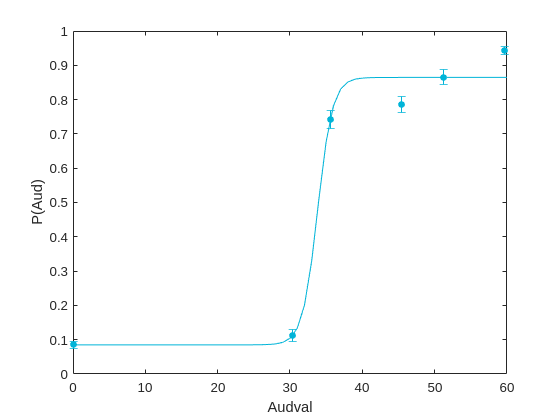

clf, hold off
rgb = [0, 0, 1; 0, 180, 216; 82, 183, 136]./ 255; %1, ["k", colcoef(1),colcoef(2)],

errorbar(valaud,mean(Acc(:,1:6)),std(Acc(:,1:6))./sqrt(P),"Marker",".","Color",rgb(2,:),"LineStyle","none","MarkerSize",15)
%scatter(valaud,Acc(1:6),50,rgb(2,:),"filled")
hold on
plot(0:1:60, (coeffvals(1)-coeffvals(2))./(1+exp(coeffvals(3).*([0:1:60] - coeffvals(4)))) + coeffvals(2),"Color",colcoef(2))
ylabel("P(Aud)"), xlabel("Audval")
ylim([0,1])
saveas(gcf, "Psyaud32.svg")

Tac

fitX = repmat(classes([1,7:end],1),P,1);
fitY = reshape(Acc(:,[1,7:end]).',1,[])';
fitX = fitX(~isnan(fitY));
fitY = fitY(~isnan(fitY));
S0 = [1 0 1 12]; 
%[fitted_curve,gof] = fit(classes([1,7:end],1),Acc([1,7:end])',fitfun,'StartPoint',S0);
[fitted_curve,gof] = fit(fitX,fitY,fitfun,'StartPoint',S0);

coeffvals = coeffvalues(fitted_curve);

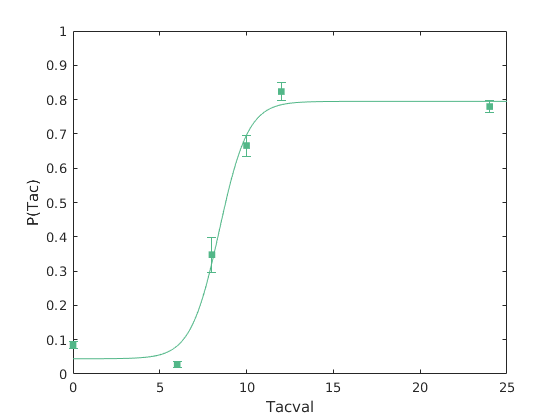

clf, hold off
%scatter(classes([1,7:end],1),Acc([1,7:end]),50,rgb(3,:),"filled")
errorbar(classes([1,7:end],1),mean(Acc(:,[1,7:end]),"omitnan"),std(Acc(:,[1,7:end]),0,"omitnan")./sqrt(P), ...
    "Marker",".","Color",rgb(3,:),"LineStyle","none","MarkerSize",15)
hold on
plot(0:0.1:25, (coeffvals(1)-coeffvals(2))./(1+exp(coeffvals(3).*([0:0.1:25] - coeffvals(4)))) + coeffvals(2),"Color",colcoef(1))
ylabel("P(Tac)"), xlabel("Tacval")
ylim([0,1])
saveas(gcf, "Psytac32.svg")

## Frequency

mini = -7; pas = 0.02; maxi = 4; 
tv = mini:pas:maxi;
lentv = length(tv);
Fr = cell(N, 1);
for n = 1:N
    Fr{n} = freq(Neu{n}, pas, 0.2, mini, maxi);
end

### **RNN**

for n = 1:N
    tasa = zeros(size(Fr{n}));
    for e = 1:E
        tasa(e,end-Psyhit{1}.f(e)+1:end) = Fr{n}(e,1:Psyhit{1}.f(e));
    end
    Fr{n} = tasa;
end

meanClass = cell(N,1);
classes = [0., 0.;
           0., 0.01;
           0., 0.05;
           0., 0.1;
           0., 0.5;
           0.01, 0.;
           0.05, 0.;
           0.1 0.;
           0.5, 0.];
C = 9; %number of classes

tv = -3.3:0.02:2.48;
lentv = 290;
for n = 1:N
    meanClass{n} = zeros(C,lentv);
    for c = 1:C
        meanClass{n}(c,:) = mean(Fr{n}(Psyhit{pi(n)}.AmpStim3 == classes(c,1) & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
    end
end

A = [];
for p =1:P
    A = [A,unique(Psyhit{P}.AmpStim3)];
end
unique(A)

ans =      0
     8
    16
    20
    24


### VPC

meanClass = cell(N,1);
classes = [0., 0.;
           0., 0.006;
           0., 0.1;
           0., 0.5;
           0., 1.;
           0., 2.5;
           6., 0.;
           8., 0.;
           10., 0.;
           12., 0.;
           24., 0.];
C = 11; %number of classes

for n = 1:N
    meanClass{n} = zeros(C,lentv);
    for c = 1:C
        if c == 10
            meanClass{n}(c,:) = mean(Fr{n}((Psyhit{pi(n)}.AmpStim3 == classes(c,1) | Psyhit{pi(n)}.AmpStim3 == 16.) ...
                & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
        elseif c == 11
            meanClass{n}(c,:) = mean(Fr{n}((Psyhit{pi(n)}.AmpStim3 == classes(c,1) | Psyhit{pi(n)}.AmpStim3 == 20.) ...
                & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
        else
            meanClass{n}(c,:) = mean(Fr{n}(Psyhit{pi(n)}.AmpStim3 == classes(c,1) & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
        end
    end
end

Vector form

meanClassvec = zeros(N,C,lentv);
    
for n = 1: N
    meanClassvec(n,:,:) = meanClass{n}(:,:);
end
%meanClassvec(isnan(meanClassvec))=0;

### Gaussian

Frg = cell(N,1);
sigma = 0.4;
for n = 1:N
    Frg{n} = convo(Neu{n}, pas, sigma, mini, maxi,2); %111,113,125
end

meanClassg = cell(N,1);

for n = 1:N
    meanClassg{n} = zeros(C,lentv);
    for c = 1:C
        meanClassg{n}(c,:) = mean(Frg{n}(Psyhit{pi(n)}.AmpStim3 == classes(c,1) & Psyhit{pi(n)}.AudStim3 == classes(c,2), :), 1);
    end
end

Plot

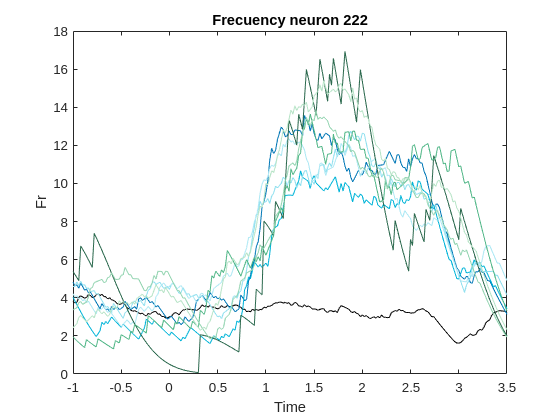

colaud = ["#03045e", "#0077b6", "#00b4d8", "#90e0ef", "#ade8f4"]; coltac = ["#081c15", "#2d6a4f", "#52b788", "#95d5b2", "#b7e4c7"];

fignames = {'Fr222.svg'};
a = 1;
for n = [222] %[126,231,251,223,36,133]
    figure(a)
    clf, hold off
    plot(tv, meanClassg{n}(1,:), "Color", "k")
    hold on
    for c = 2:5
        plot(tv, meanClassg{n}(c+1,:), "Color", colaud(c))
    end
    xlim([-1,3.5])
    for c = 2:5
        plot(tv, meanClassg{n}(c+6,:), "Color", coltac(c))
    end
    ylabel("Fr"), xlabel("Time")
    title(strcat("Frecuency neuron ", num2str(n)))
    saveas(gcf, fignames{a})
    a = a + 1;
end

## GLM

ncoef = 4; %Aud, Tac, AmpAud, AmpTac
%Stimulus : i = tv(351); e = tv(376);. Delay : i = tv(401); e = tv(476);
tws = [1.,2.5]; %  Stimulus : 0.3,0.6; Delay : 1, 2; Response : 3.1,3.4;
meantw = cell(N,1);
coef = zeros(N,ncoef + 1); % + b

for n = 1:N
    nens = length(Fr{n}(:,1));
    meantw{n} = zeros(nens,length(tws(1,:)));
    for e = 1:nens
        meantw{n}(e,1) = mean(Fr{n}(e,tv > tws(1,1) & tv < tws(1,2)));
    end

    pred = zeros(nens, ncoef); 
    pred(:, 1) = int16(Psyhit{pi(n)}.AmpStim3 > 0);
    pred(:, 2) = int16(Psyhit{pi(n)}.AudStim3 > 0);
    pred(:, 3) = Psyhit{pi(n)}.AmpStim3;% / 24.0;
    pred(:, 4) = Psyhit{pi(n)}.AudStim3;% / 2.5;
    
    coef(n,:) = glmfit(pred,meantw{n}(:,1),"poisson","link","identity","B0",[mean(meantw{n}(:,1)),0.,0.,0.,0.]);
end


coef(isnan(coef)) = 0;

Plot distribution of coefficients

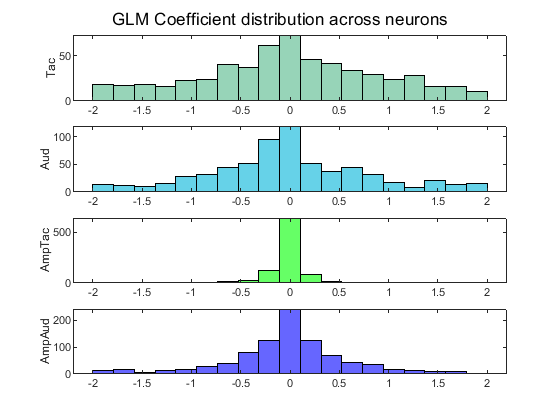

colcoef = ["#52b788", "#00b4d8", "g", "b"];
bins = linspace(-2,2,20); %(-6,6,20)
clf, hold off
subplot(4,1,1)
histogram(coef(:,2), bins,"FaceColor", colcoef(1))
ylabel("Tac")
subplot(4,1,2)
histogram(coef(:,3), bins, "FaceColor", colcoef(2))
ylabel("Aud")
subplot(4,1,3)
histogram(coef(:,4), bins, "FaceColor", colcoef(3))
ylabel("AmpTac")
subplot(4,1,4)
histogram(coef(:,5), bins, "FaceColor", colcoef(4))
ylabel("AmpAud")
sgtitle("GLM Coefficient distribution across neurons")

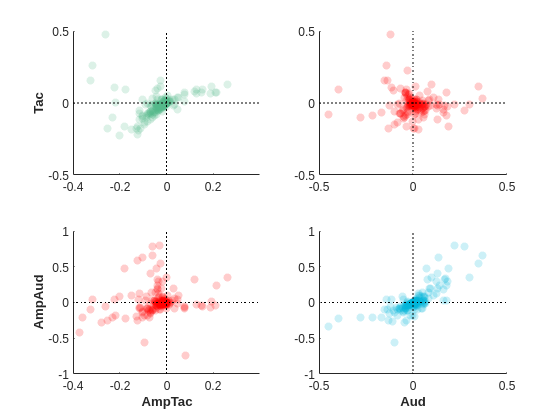

clf, hold off
lim1 = 0.4;
lim2 = 0.5;
lim3 = 0.5;
lim4 = 1;
subplot(2,2,1)
scatter(coef(:,4),coef(:,2), "MarkerFaceColor", colcoef(1), "MarkerFaceAlpha", 0.2,"MarkerEdgeColor","none")
hold on
plot([-40,40],[0,0],"Color","k","LineStyle",":")
plot([0,0],[-70,70],"Color","k","LineStyle",":")
xlim([-lim1,lim1]), ylim([-lim2,lim2])
ylabel("Tac",FontWeight="bold")
subplot(2,2,2)
scatter(coef(:,3), coef(:,2), "MarkerFaceColor", "red", "MarkerFaceAlpha", 0.2,"MarkerEdgeColor","none")
hold on
plot([-40,40],[0,0],"Color","k","LineStyle",":")
plot([0,0],[-70,70],"Color","k","LineStyle",":")
xlim([-lim3,lim3]), ylim([-lim2,lim2])
subplot(2,2,3)
scatter(coef(:,4),coef(:,5), "MarkerFaceColor", "red", "MarkerFaceAlpha", 0.2,"MarkerEdgeColor","none")
hold on
plot([-40,40],[0,0],"Color","k","LineStyle",":")
plot([0,0],[-15,15],"Color","k","LineStyle",":")
xlim([-lim1,lim1]), ylim([-lim4,lim4])
xlabel("AmpTac",FontWeight="bold"), ylabel("AmpAud",FontWeight="bold")
subplot(2,2,4)
scatter(coef(:,3),coef(:,5), "MarkerFaceColor", colcoef(2), "MarkerFaceAlpha", 0.2,"MarkerEdgeColor","none")
hold on
plot([-40,40],[0,0],"Color","k","LineStyle",":")
plot([0,0],[-15,15],"Color","k","LineStyle",":")
xlim([-lim3,lim3]), ylim([-lim4,lim4])
xlabel("Aud",FontWeight="bold")

%saveas(gcf, "GLMcoefRNN2.svg")

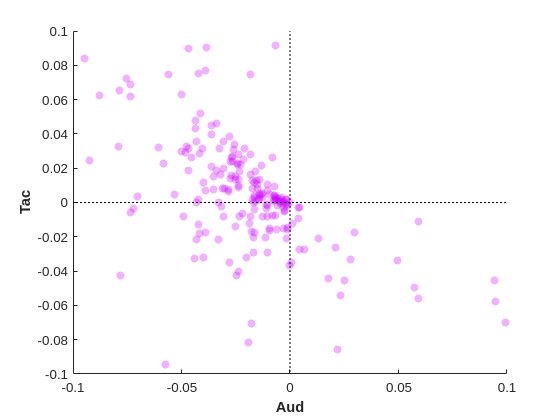

coef = coef05to15;
clf, hold off
lim3 = 0.1;
lim2 = 0.1;
scatter(coef(:,3), coef(:,2), "MarkerFaceColor", "#CC00FF", "MarkerFaceAlpha", 0.3,"MarkerEdgeColor","none")
hold on
plot([-40,40],[0,0],"Color","k","LineStyle",":")
plot([0,0],[-70,70],"Color","k","LineStyle",":")
xlim([-lim3,lim3]), ylim([-lim2,lim2])
ylabel("Tac",FontWeight="bold")
xlabel("Aud",FontWeight="bold")
saveas(gcf, "GLMcoefRNN2.svg")

%[b,~,~,~,stats] = regress(coef(:,5),[ones(N,1) coef(:,3)])
%coef = coef0to05;
for c = 1:4
    for ol = 1:15
        [~, maxi] = max(coef(:,c));
        [~, mini] = min(coef(:,c));
        coef([maxi,mini],c) = nan;
    end
end



c = corrcoef(coef(:,4),coef(:,2),Rows="pairwise");
c(1,2)

ans = 0.4005

c = corrcoef(coef(:,3),coef(:,2),Rows="pairwise");
c(1,2)

ans = -0.1550

c = corrcoef(coef(:,4),coef(:,5),Rows="pairwise");
c(1,2)

ans = -0.0111

c = corrcoef(coef(:,3),coef(:,5),Rows="pairwise");
c(1,2)

ans = 0.2356

### Proyection in coefficients

%coef = coef0to05;
normcoef = zeros(size(coef));
proyec = zeros(ncoef + 1, C + 2, lentv);


for c = 2:ncoef + 1 %without bias
    normcoef(:,c) = coef(:,c) ./ norm(coef(:,c));

    for t = 1:lentv
        for s = 1:C
            proyec(c, s, t) = meanClassvec(:, s, t)'*normcoef(:,c);
        end
        proyec(c, end - 1, t) = mean(meanClassvec(:,2:5 , t), 2, "omitnan")'*normcoef(:,c); %All Aud 3:6
        proyec(c, end, t) = mean(meanClassvec(:, 6:end, t), 2, "omitnan")'*normcoef(:,c); %All Tac 7:end
    end
end

Ploting mod

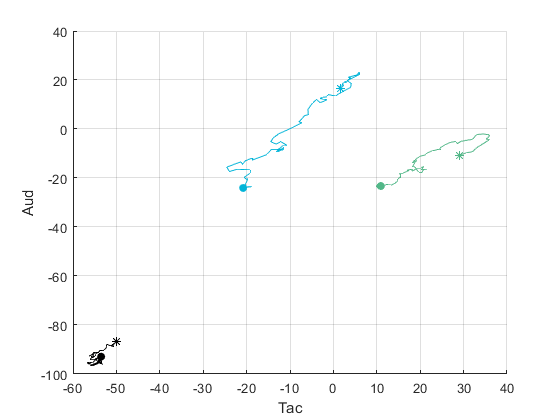

%Stimulus : i = tv(351); e = tv(376);. Delay : i = tv(401); e = tv(476);
i = tv(401); e = tv(476); %e = 3.5 tv(526), 0.5 tv(376)
wind = tv >= i & tv <= e;
rgb = [0, 0, 1; 0, 180, 216; 82, 183, 136]./ 255; %1, ["k", colcoef(1),colcoef(2)],

clf, hold off
scatter([proyec(2,1,tv == i), proyec(2,end - 1,tv == i), proyec(2,end,tv == i)], ...
    [proyec(3,1,tv == i), proyec(3,end-1,tv == i), proyec(3,end,tv == i)], [], rgb, Marker="*")
hold on

scatter([proyec(2,1,tv == e), proyec(2,end - 1,tv == e), proyec(2,end,tv == e)], ...
    [proyec(3,1,tv == e), proyec(3,end-1,tv == e), proyec(3,end,tv == e)], [], rgb, "filled", Marker="o")

plot(squeeze(proyec(2,1,wind)), squeeze(proyec(3,1,wind)), "color", "k")
plot(squeeze(proyec(2,end - 1,wind)), squeeze(proyec(3,end - 1,wind)), "color", colcoef(2))
plot(squeeze(proyec(2,end,wind)), squeeze(proyec(3,end,wind)), "color", colcoef(1))
grid on
xlabel("Tac"), ylabel("Aud")%, title("Proyection")

%saveas(gcf, "GLMRNN_6.svg")

Ploting Amp

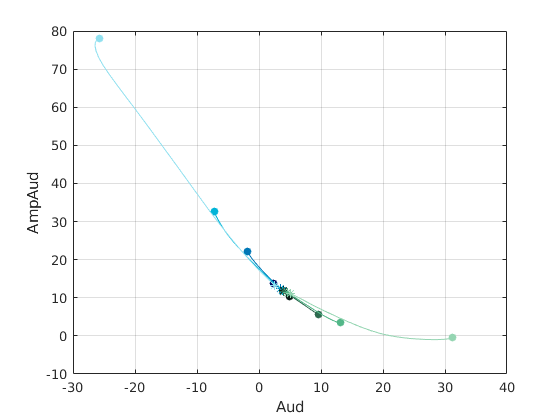

coef1 = 4; 
coef2 = 5;
colaud = ["#03045e", "#0077b6", "#00b4d8", "#90e0ef", "#ade8f4"]; coltac = ["#081c15", "#2d6a4f", "#52b788", "#95d5b2", "#b7e4c7"];

clf, hold off
plot(squeeze(proyec(coef1,1,wind)), squeeze(proyec(coef2,1,wind)), "color", "k")
hold on
scatter(proyec(coef1,1,tv == i), proyec(coef2,1,tv == i), "MarkerEdgeColor","k", Marker="*")
scatter(proyec(coef1,1,tv == e), proyec(coef2,1,tv == e),"MarkerFaceColor","k","MarkerEdgeColor","none")
for c = 2:5%3:6
    plot(squeeze(proyec(coef1,c,wind)), squeeze(proyec(coef2,c,wind)), "color", colaud(c-1))
    scatter(proyec(coef1,c,tv == i), proyec(coef2,c,tv == i), "MarkerEdgeColor",colaud(c-1), Marker="*")
    scatter(proyec(coef1,c,tv == e), proyec(coef2,c,tv == e),"MarkerFaceColor",colaud(c-1),"MarkerEdgeColor","none")

end
for c = 6:C%7:C
    plot(squeeze(proyec(coef1,c,wind)), squeeze(proyec(coef2,c,wind)), "color", coltac(c-5))
    scatter(proyec(coef1,c,tv == i), proyec(coef2,c,tv == i), "MarkerEdgeColor",coltac(c-5), Marker="*")
    scatter(proyec(coef1,c,tv == e), proyec(coef2,c,tv == e), "MarkerFaceColor", coltac(c-5),"MarkerEdgeColor","none")
end
grid on

xlabel("Aud"), ylabel("AmpAud")%, title("Proyection")

%saveas(gcf, "GLMRNN_4.svg")

%coef0to05 = coef;
coef1to2 = coef;

acos(normcoef(:,2).'*normcoef(:,3))*180/3.1416

ans = 60.8752

Cosine

cosEstDel = coef03to06(:,2)'*coef1to2(:,2) ./ (norm(coef03to06(:,2))*norm(coef1to2(:,2)))
cosEstDel = coef1to2(:,2)'*coef1to2(:,3) ./ (norm(coef1to2(:,2))*norm(coef1to2(:,3)))

Check orthogonal

coef1 = 2; 
coef2 = 3;
difang = zeros(4*4,1);
c = 1;

for c1 = 8:C
    for c2 = 3:6      
        alfa = regress(squeeze(proyec(coef2,c1,wind)), [ones(sum(wind),1), squeeze(proyec(coef1,c1,wind))]);
        beta = regress(squeeze(proyec(coef2,c2,wind)), [ones(sum(wind),1), squeeze(proyec(coef1,c2,wind))]);
        difang(c) = atan(beta(2)) * 180/3.141592 - atan(alfa(2)) * 180/3.141592 ;
       c = c+1;
    end
end

clf, hold off
histogram(difang,"FaceColor","r",Normalization="probability")
xlabel("Angle °")

TODO Errors

proyecErr = zeros(ncoef + 1, 1, lentv);
meanErr = zeros(N,1,lentv);

for c = 2:ncoef + 1 %without bias

    for n = 1: N
        meanErr(n,1,:) = 5;
    end
    meanClassvec(isnan(meanClassvec))=0;
    for t = 1:lentv
        for s = 1:C
            proyec(c, s, t) = meanClassvec(:, s, t)'*normcoef(:,c);
        end
        proyec(c, end - 1, t) = mean(meanClassvec(:, 3:6, t), 2, "omitnan")'*normcoef(:,c); %All Aud
        proyec(c, end, t) = mean(meanClassvec(:, 7:end, t), 2, "omitnan")'*normcoef(:,c); %All Tac
    end
end

## MLM

ncoef = 2; %AmpAud, AmpTac
tws = [0.,0.5]; %  Used = 0.,0.5, Tryed : 0.3,0.6; 1, 2; 3.1,3.4
meantw = cell(N,1);
MLMcoef = zeros(N,ncoef + 1,1000); % + b
MLMcoef_s = zeros(N,ncoef + 1);

for n = 1:N
    nens = length(Fr{n}(:,1));
    meantw{n} = zeros(nens,1);
    for e = 1:nens
        meantw{n}(e,1) = mean(Fr{n}(e,tv > tws(1,1) & tv < tws(1,2)));
    end

    pred = ones(nens, ncoef+1); 
    pred(:,1) = Psyhit{pi(n)}.AmpStim3;% / 24.0;
    pred(:, 2) = Psyhit{pi(n)}.AudStim3;% / 2.5;
    
    MLMcoef_s(n,:) = regress(meantw{n},pred);    
    for b = 1 : 1000 %bootstrap
        br = randsample(nens,nens,true);
        MLMcoef(n,:,b) = regress(meantw{n}(br),pred(br,:));    
    end
end

MLMcoef(isnan(MLMcoef)) = 0;
MLMcoef_s(isnan(MLMcoef_s)) = 0;

Detection vector

Detvec = zeros(N,2);
i = tv(351); e = tv(476); %tv(376); 

Detvec(:,1) = meanClassvec(:,6,tv == e) - meanClassvec(:,6,tv == i);
Detvec(:,2) = meanClassvec(:,11,tv == e) - meanClassvec(:,11,tv == i);

A = MLMcoef_s(:,2); % AmpTac, AmpAud
B = Detvec(:,1); % DetAud, DetTac
angle = acos(A'*B ./ (norm(A)*norm(B)))*180/3.1416

angle = 101.0036

Check orthogonal

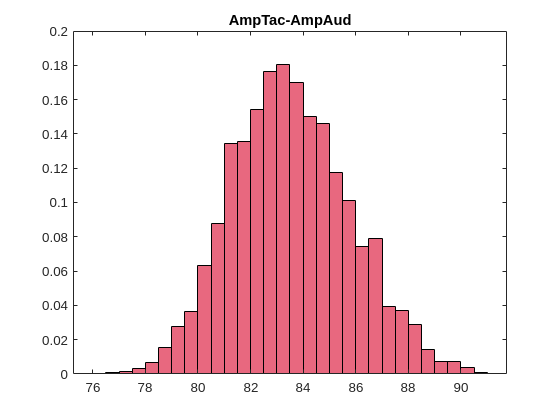

Angles = zeros(100*99/2,1);
a = 1;
for b1 = 1:99
    for b2 = b1+1:100
        A = MLMcoef(:,1,b1);
        B = MLMcoef(:,2,b2);
        Angles(a) = acos(A'*B ./ (norm(A)*norm(B)))*180/3.1416;
        a = a + 1;
    end
end

clf, hold off
histogram(Angles,Normalization="pdf",FaceColor="#d90429")
title("AmpTac-AmpAud")

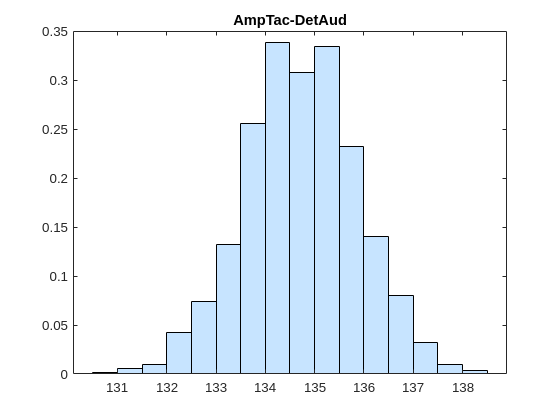

angle = 79.3590

Angles2 = zeros(100,1);
a = 1;
for b1 = 1:1000
    A = MLMcoef(:,1,b1);
    B = Detvec(:,2);
    Angles2(a) = acos(A'*B ./ (norm(A)*norm(B)))*180/3.1416;
    a = a + 1;
end

clf, hold off
histogram(Angles2,Normalization="pdf",FaceColor="#a2d2ff")
title("AmpTac-DetAud")

### Proyection in coefficients

coef = [MLMcoef_s(:,1:2), Detvec];
ncoef = 4;
normcoef = zeros(size(coef));
proyec = zeros(ncoef, C + 2, lentv);

meanClassvec(isnan(meanClassvec)) = 0;
for c = 1:ncoef
    normcoef(:,c) = coef(:,c) ./ norm(coef(:,c));

    for t = 1:lentv
        for s = 1:C
            proyec(c, s, t) = meanClassvec(:, s, t)'*normcoef(:,c);
        end
        proyec(c, end - 1, t) = mean(meanClassvec(:,2:6 , t), 2, "omitnan")'*normcoef(:,c); %All Aud 3:6
        proyec(c, end, t) = mean(meanClassvec(:, 7:end, t), 2, "omitnan")'*normcoef(:,c); %All Tac 7:end
    end
end

Ploting mod

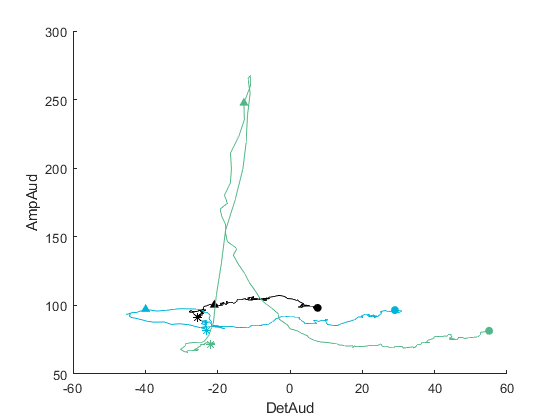

i = tv(326); i2 = tv(376); e = tv(476); %e = tv(376); %e = 3.5 tv(526), 0.5 tv(376)
c1 = 4; c2 = 1; % AmpTac, AmpAud, DetAud, DetTac
wind = tv >= i & tv <= e;
rgb = [0, 0, 1; 0, 180, 216; 82, 183, 136]./ 255; %1, ["k", colcoef(1),colcoef(2)],

clf, hold off
scatter([proyec(c1,1,tv == i), proyec(c1,end - 1,tv == i), proyec(c1,end,tv == i)], ...
    [proyec(c2,1,tv == i), proyec(c2,end-1,tv == i), proyec(c2,end,tv == i)], [], rgb, Marker="*")
hold on

scatter([proyec(c1,1,tv == i2), proyec(c1,end - 1,tv == i2), proyec(c1,end,tv == i2)], ...
    [proyec(c2,1,tv == i2), proyec(c2,end-1,tv == i2), proyec(c2,end,tv == i2)], [], rgb, "filled",Marker="^")

scatter([proyec(c1,1,tv == e), proyec(c1,end - 1,tv == e), proyec(c1,end,tv == e)], ...
    [proyec(c2,1,tv == e), proyec(c2,end-1,tv == e), proyec(c2,end,tv == e)], [], rgb, "filled", Marker="o")

plot(squeeze(proyec(c1,1,wind)), squeeze(proyec(c2,1,wind)), "color", "k")
plot(squeeze(proyec(c1,end - 1,wind)), squeeze(proyec(c2,end - 1,wind)), "color", colcoef(2))
plot(squeeze(proyec(c1,end,wind)), squeeze(proyec(c2,end,wind)), "color", colcoef(1))
%ylim([10,122])
%xlim([50,275])
%grid on
xlabel("DetAud"), ylabel("AmpAud")%, title("Proyection")

%saveas(gcf, "Carn_Aud.svg")

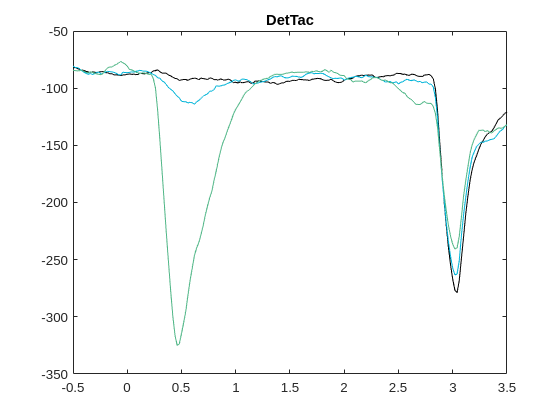

c1 = 4;
names = ["AmpTac", "AmpAud", "DetAud", "DetTac"];
clf, hold off
plot(tv, squeeze(proyec(c1,1,:)), "color", "k")
hold on
plot(tv, squeeze(proyec(c1,end - 1,:)), "color", colcoef(2))
plot(tv, squeeze(proyec(c1,end,:)), "color", colcoef(1))
xlim([-0.5,3.5])
title(names(c1))

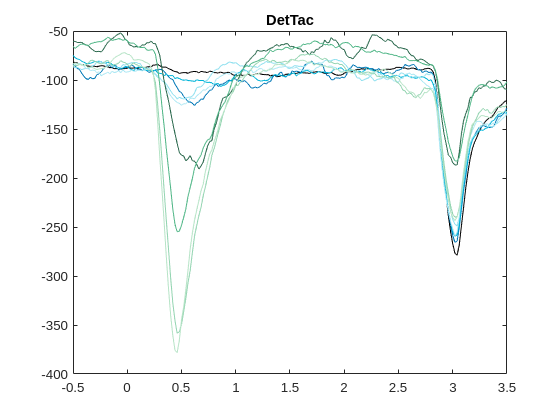

c1 = 4;
clf, hold off
plot(tv, squeeze(proyec(c1,1,:)), "color", "k")
hold on
for c = 3:6 %AUD no lower class
    plot(tv,squeeze(proyec(c1,c,:)),"color",colaud(c-1))
end
for c = 8:11 %TAC no lower class
    plot(tv,squeeze(proyec(c1,c,:)),"color",coltac(c-6))
end

xlim([-0.5,3.5])
title(names(c1))

## Mutual Information

i = tv(326); e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
Ps = [1/3, 1/3, 1/3]; IM = zeros(N,lenwin);

for n = 1:N
    for t1 = 1: lenwin
        t = t1 + 325;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        
        Psr1 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.,t), ... 
            ed,"Normalization","probability");
        Psr2 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.,t), ...
            ed,"Normalization","probability");
        Psr3 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.,t), ...
            ed,"Normalization","probability");
        IM(n,t1) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");        
    end

end

for n = 140
    %figure(n)
    clf, hold off
    plot(tv(wind),IM(n,:),"color", "#f48c06","LineWidth", 1)
    title(["Información mutua neurona", num2str(n)]), xlabel("Time"), ylabel("bits")
    xlim([-2,3.5])
end

#### Permutations

IMp = zeros(N,lenwin, 1000);

for n = 1:N
    n
    for t1 = 1:lenwin
        t = t1 + 325;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        Frp = Fr{n}(:,t);

        for p = 1:1000
        Frp = Frp(randperm(length(Frp)));

        Psr1 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.), ...
            ed,"Normalization","probability");
        Psr2 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.), ...
            ed,"Normalization","probability");
        Psr3 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.), ...
            ed,"Normalization","probability");
        IMp(n,t1,p) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");
        end
    end
end

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

n = 11

n = 12

n = 13

n = 14

n = 15

n = 16

n = 17

n = 18

n = 19

n = 20

n = 21

n = 22

n = 23

n = 24

n = 25

n = 26

n = 27

n = 28

n = 29

n = 30

n = 31

n = 32

n = 33

n = 34

n = 35

n = 36

n = 37

n = 38

n = 39

n = 40

n = 41

n = 42

n = 43

n = 44

n = 45

n = 46

n = 47

n = 48

n = 49

n = 50

n = 51

n = 52

n = 53

n = 54

n = 55

n = 56

n = 57

n = 58

n = 59

n = 60

n = 61

n = 62

n = 63

n = 64

n = 65

n = 66

n = 67

n = 68

n = 69

n = 70

n = 71

n = 72

n = 73

n = 74

n = 75

n = 76

n = 77

n = 78

n = 79

n = 80

n = 81

n = 82

n = 83

n = 84

n = 85

n = 86

n = 87

n = 88

n = 89

n = 90

n = 91

n = 92

n = 93

n = 94

n = 95

n = 96

n = 97

n = 98

n = 99

n = 100

n = 101

n = 102

n = 103

n = 104

n = 105

n = 106

n = 107

n = 108

n = 109

n = 110

n = 111

n = 112

n = 113

n = 114

n = 115

n = 116

n = 117

n = 118

n = 119

n = 120

n = 121

n = 122

n = 123

n = 124

n = 125

n = 126

n = 127

n = 128

n = 129

n = 130

n = 131

n = 132

n = 133

n = 134

n = 135

n = 136

n = 137

n = 138

n = 139

n = 140

n = 141

n = 142

n = 143

n = 144

n = 145

n = 146

n = 147

n = 148

n = 149

n = 150

n = 151

n = 152

n = 153

n = 154

n = 155

n = 156

n = 157

n = 158

n = 159

n = 160

n = 161

n = 162

n = 163

n = 164

n = 165

n = 166

n = 167

n = 168

n = 169

n = 170

n = 171

n = 172

n = 173

n = 174

n = 175

n = 176

n = 177

n = 178

n = 179

n = 180

n = 181

n = 182

n = 183

n = 184

n = 185

n = 186

n = 187

n = 188

n = 189

n = 190

n = 191

n = 192

n = 193

n = 194

n = 195

n = 196

n = 197

n = 198

n = 199

n = 200

n = 201

n = 202

n = 203

n = 204

n = 205

n = 206

n = 207

n = 208

n = 209

n = 210

n = 211

n = 212

n = 213

n = 214

n = 215

n = 216

n = 217

n = 218

n = 219

n = 220

n = 221

n = 222

n = 223

n = 224

n = 225

n = 226

n = 227

n = 228

n = 229

n = 230

n = 231

n = 232

n = 233

n = 234

n = 235

n = 236

n = 237

n = 238

n = 239

n = 240

n = 241

n = 242

n = 243

n = 244

n = 245

n = 246

n = 247

n = 248

n = 249

n = 250

n = 251

n = 252

n = 253

n = 254

n = 255

n = 256

n = 257

n = 258

n = 259

n = 260

n = 261

n = 262

n = 263

n = 264

n = 265

n = 266

n = 267

n = 268

n = 269

n = 270

n = 271

n = 272

n = 273

n = 274

n = 275

n = 276

n = 277

n = 278

n = 279

n = 280

n = 281

n = 282

n = 283

n = 284

n = 285

n = 286

n = 287

n = 288

n = 289

n = 290

n = 291

n = 292

n = 293

n = 294

n = 295

n = 296

n = 297

n = 298

n = 299

n = 300

n = 301

n = 302

n = 303

n = 304

n = 305

n = 306

n = 307

n = 308

n = 309

n = 310

Significance

P05IM = false(N,lenwin);
for n = 1:N
    Pr = sum(IMp(n,:,:) >= IM(n,:), 3)./1000;
    P05 = Pr < 0.05;

    for t = 1:lenwin - 2 %cluster correction
        if P05(t) == true && P05(t+1) == true && P05(t+2) == true
            P05IM(n,[t,t+1,t+2]) = true;
        end
    end 
end

Population randomness

IMrp = zeros(1,lenwin);

for t1 = 1:lenwin
    t = t1 + 325;
    for p = 1:5
        rp = zeros(1,5);
        for n = 1:N
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        Pt = histcounts(Fr{n}(:,t),ed,"Normalization","probability");
        Frp = Fr{n}(:,t);

        
        Frp = Frp(randperm(length(Frp)));

        Psr1 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.), ...
            ed,"Normalization","probability");
        Psr2 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.), ...
            ed,"Normalization","probability");
        Psr3 = histcounts(Frp(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.), ...
            ed,"Normalization","probability");
        im = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan") + Ps(3)*sum(Psr3.*log2(Psr3./Pt),"omitnan");
        if sum(IMp(n,t1,:) >= im)/1000 < 0.05
            rp(p) = rp(p) + 1; 
        end
        end
    end
    IMrp(t1) = mean(rp);
end

Plotting:

Individual

for n = [1,17]
    figure(n)
    clf, hold off
    plot(tv(wind),IM(n,:),"color", "#f48c06","LineWidth", 1)
    hold on
    scatter(tv(P05IM(n,:)), 0.05*ones(length(tv(P05IM(n,:))), 1), 10, "filled", "MarkerFaceColor","#4361ee")
    title(["Información mutua neurona", num2str(n)]), xlabel("Time"), ylabel("bits")
    xlim([-2,3.5])
end

P05IM = cat(1,P05IM32d, P05IM32i, P05IM33);
IMrp = mean([IMrp32d; IMrp32i; IMrp33]);

Population

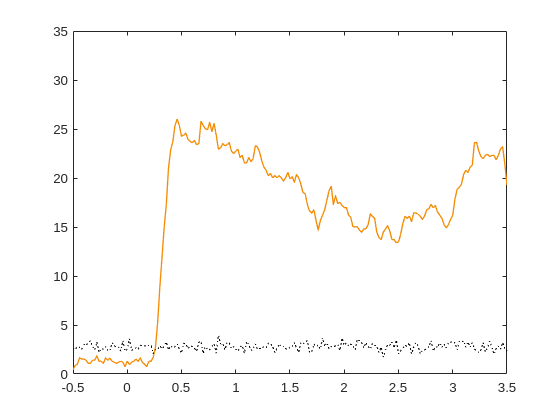

clf, hold off
plot(tv(wind),sum(P05IM)./N * 100,"color", "#f48c06","LineWidth", 1)
hold on
plot(tv(wind),IMrp,"color","k","Linestyle",":")
%title("% of neurons with significant Mutual Information")
%xlabel("Time"), ylabel("%")
ylim([0,35])
xlim([-0.5,3.5])
saveas(gcf, "VPCALL%IM.svg")

Latency

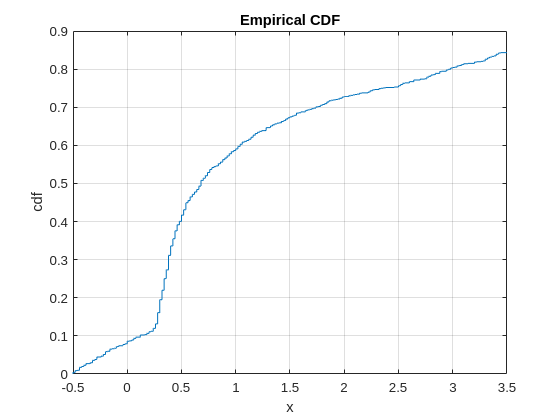

Lat = nan(1,N);
for n = 1:N
    t = tv(wind);
    if sum(P05IM(n,:)) > 0
        Lat(n) = t(find(P05IM(n,:) == 1,1));
    end
end
Lat(isnan(Lat)) = 4;

clf, hold off
cdfplot(Lat)
xlim([-0.5,3.5])
ylabel("cdf")
saveas(gcf, "cdf_Lat.svg")

## Mutual Information pair

i = tv(326); ii = 326; e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
Ps = [1/2, 1/2]; IMpair = zeros(N,lenwin,3); %TA,TN,AN

for n = 1:N
    for t1 = 1: lenwin
        t = t1 + 325;
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        FrT = Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.,t);
        FrA = Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.,t);
        FrN = Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.,t);

        %TA
        Frp = [FrT;FrA];
        Psr1 = histcounts(Frp(1:length(FrT)), ed,"Normalization","probability");
        Psr2 = histcounts(Frp(length(FrT)+1:end), ed,"Normalization","probability");
        Pt = histcounts(Frp, ed,"Normalization","probability");
        IMpair(n,t1,1) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");
        
        %TN
        Frp = [FrT;FrN];
        Psr1 = histcounts(Frp(1:length(FrT)), ed,"Normalization","probability");
        Psr2 = histcounts(Frp(length(FrT)+1:end), ed,"Normalization","probability");
        Pt = histcounts(Frp, ed,"Normalization","probability");
        IMpair(n,t1,2) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");

        %AN
        Frp = [FrA;FrN];
        Psr1 = histcounts(Frp(1:length(FrA)), ed,"Normalization","probability");
        Psr2 = histcounts(Frp(length(FrA)+1:end), ed,"Normalization","probability");
        Pt = histcounts(Frp, ed,"Normalization","probability");
        IMpair(n,t1,3) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");
    end
end

Plot

clf, hold off
plot(tv(wind),mean(IMpair(:,:,1),1),"color", "r","LineWidth", 1)
hold on
plot(tv(wind),mean(IMpair(:,:,2),1),"color", colcoef(1),"LineWidth", 1)
plot(tv(wind),mean(IMpair(:,:,3),1),"color", colcoef(2),"LineWidth", 1)
xlim([-0.5,3.5])
legend(["TA","TN","AN"])

### Permutations and significance

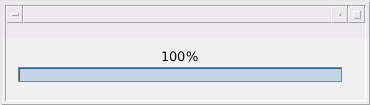

IMpairs = zeros(N, lenwin, 3);
IMpairpr = zeros(4, lenwin);
wb = waitbar(0);

for t1 = 1:110%lenwin
    t = t1 + 325;
    waitbar(t1/lenwin, wb, strcat(num2str(round(t1/lenwin*100,2)),"%"))
    
    IMpairp = zeros(N, 3, 1000);
    for n = 1:N
        ed = linspace(min(Fr{n}(:,t),[],"all"),max(Fr{n}(:,t),[],"all"),10);
        FrT = Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.,t);
        FrA = Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.,t);
        FrN = Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.,t);

        for p = 1:1000
            %TA
            Frp = [FrT;FrA];
            Frp = Frp(randperm(length(Frp)));
            Psr1 = histcounts(Frp(1:length(FrT)), ed,"Normalization","probability");
            Psr2 = histcounts(Frp(length(FrT)+1:end), ed,"Normalization","probability");
            Pt = histcounts(Frp, ed,"Normalization","probability");
            IMpairp(n,1,p) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");
            
            %TN
            Frp = [FrT;FrN];
            Frp = Frp(randperm(length(Frp)));
            Psr1 = histcounts(Frp(1:length(FrT)), ed,"Normalization","probability");
            Psr2 = histcounts(Frp(length(FrT)+1:end), ed,"Normalization","probability");
            Pt = histcounts(Frp, ed,"Normalization","probability");
            IMpairp(n,2,p) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");

            %AN
            Frp = [FrA;FrN];
            Frp = Frp(randperm(length(Frp)));
            Psr1 = histcounts(Frp(1:length(FrA)), ed,"Normalization","probability");
            Psr2 = histcounts(Frp(length(FrA)+1:end), ed,"Normalization","probability");
            Pt = histcounts(Frp, ed,"Normalization","probability");
            IMpairp(n,3,p) = Ps(1)*sum(Psr1.*log2(Psr1./Pt),"omitnan") + Ps(2)*sum(Psr2.*log2(Psr2./Pt),"omitnan");

        end
        
        IMpairs(n,t1,:) = mean(squeeze(IMpair(n,t1,:)) < squeeze(IMpairp(n,:,:)),2) < 0.05;
        
    end

    %population randomess
    for p =1:5
        IMpairpm = mean(squeeze(IMpairp(:,:,p)) < IMpairp, 3) < 0.05;
    
        IMpairpr(1,t1) = IMpairpr(1,t1) + mean(IMpairpm(:,1) & IMpairpm(:,2) & IMpairpm(:,3))/5;
        IMpairpr(2,t1) = IMpairpr(2,t1) + mean(IMpairpm(:,1) & IMpairpm(:,2) & ~IMpairpm(:,3))/5;
        IMpairpr(3,t1) = IMpairpr(3,t1) + mean(IMpairpm(:,1) & ~IMpairpm(:,2) & IMpairpm(:,3))/5;
        IMpairpr(4,t1) = IMpairpr(4,t1) + mean(~IMpairpm(:,1) & IMpairpm(:,2) & IMpairpm(:,3))/5;
    end
end

Porcentages = cell(1,4);
i = 1 + 264 + 310; e = N; %monkey by monkey %264, 310 345

Porcentages{1} = mean(IMpairs(i:e,:,1) & IMpairs(i:e,:,2) & IMpairs(i:e,:,3),1);
Porcentages{2} = mean(IMpairs(i:e,:,1) & IMpairs(i:e,:,2) & ~IMpairs(i:e,:,3),1);
Porcentages{3} = mean(IMpairs(i:e,:,1) & ~IMpairs(i:e,:,2) & IMpairs(i:e,:,3),1);
Porcentages{4} = mean(~IMpairs(i:e,:,1) & IMpairs(i:e,:,2) & IMpairs(i:e,:,3),1);
for c = 1:4
    Porcentages{c} = Porcentages{c} - mean(Porcentages{c}(1:25));
    Porcentages{c}(Porcentages{c} < 0) = 0;
end

Ploting

Population

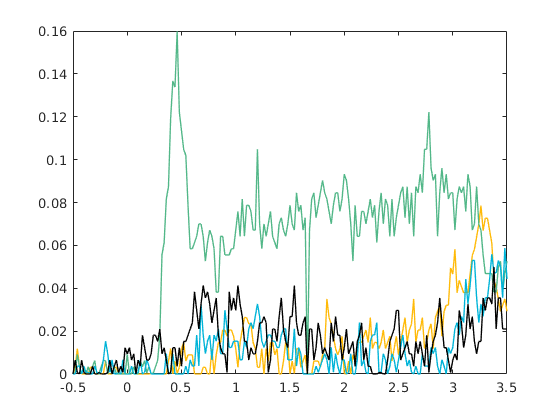

clf, hold off
%TA,TN,AN
plot(tv(wind),Porcentages{1},"color", "#ffba08","LineWidth", 1)
hold on
plot(tv(wind),Porcentages{2},"color", colcoef(1),"LineWidth", 1)
plot(tv(wind),Porcentages{3},"color", colcoef(2),"LineWidth", 1)
plot(tv(wind),Porcentages{4},"color", "k","LineWidth", 1)
xlim([-0.5,3.5])
%legend(["3","T","A","N"])
saveas(gcf, "IM_p33.svg")

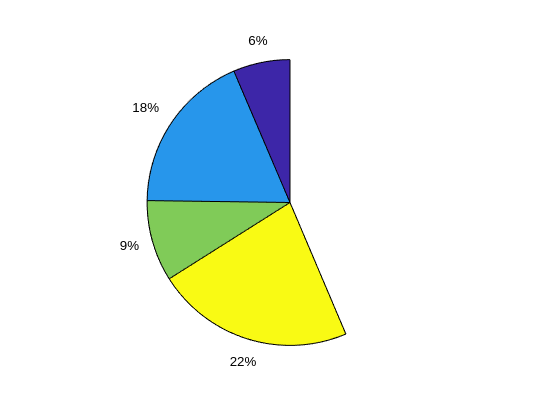

t = 1.5;
IMvec = sum(P05IM)./N * 100;
Pie_data = [Porcentages{1}(tv(wind) == t),Porcentages{2}(tv(wind) == t),...
    Porcentages{3}(tv(wind) == t),Porcentages{4}(tv(wind) == t)]./IMvec(tv(wind) == t);
clf, hold off
pie(Pie_data)%,["all","T","a","n"])

%saveas(gcf, "IM_pie1.5.svg")

### Time cluster and latency

Clusters in time

Codpairs = zeros(N, lenwin, 4);
for n = 1:N
    cod(1,:) = IMpairs(n,:,1) & IMpairs(n,:,2) & IMpairs(n,:,3);
    cod(2,:) = IMpairs(n,:,1) & IMpairs(n,:,2) & ~IMpairs(n,:,3);
    cod(3,:) = IMpairs(n,:,1) & ~IMpairs(n,:,2) & IMpairs(n,:,3);
    cod(4,:) = ~IMpairs(n,:,1) & IMpairs(n,:,2) & IMpairs(n,:,3);
    for c = 1:4
        for t = 1:lenwin-2
            if cod(c,t) == 1 && cod(c,t + 1) == 1 && cod(c,t + 2) == 1
                Codpairs(n,t:t+2,c) = 1;
            end
        end
    end
end

Individual

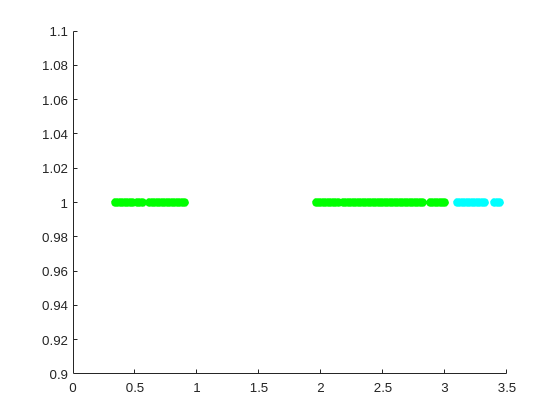

n = 264 + + 310 + 260;%264 + 310 + ;

clf, hold off
scatter(tv(wind),Codpairs(n,:,3),"cyan",Marker="o",MarkerFaceColor="flat")

hold on
scatter(tv(wind),Codpairs(n,:,4),"k",Marker="o",MarkerFaceColor="flat")
scatter(tv(wind),Codpairs(n,:,2),"green",Marker="o",MarkerFaceColor="flat")
scatter(tv(wind),Codpairs(n,:,1),"m",Marker="o",MarkerFaceColor="flat")
xlim([0,3.5])
ylim([0.9,1.1])
saveas(gcf, "IM_p260.svg")

Latency

Latencies = nan(N,4);
cod = zeros(4,lenwin);

for n = 1:N
    cod(1,:) = IMpairs(n,:,1) & IMpairs(n,:,2) & IMpairs(n,:,3);
    cod(2,:) = IMpairs(n,:,1) & IMpairs(n,:,2) & ~IMpairs(n,:,3);
    cod(3,:) = IMpairs(n,:,1) & ~IMpairs(n,:,2) & IMpairs(n,:,3);
    cod(4,:) = ~IMpairs(n,:,1) & IMpairs(n,:,2) & IMpairs(n,:,3);
    for c = 1:4
        l = 0;
        t = 26; %no prestim
        while t < lenwin - 2 && l == 0
            if cod(c,t) == 1 && cod(c,t + 1) == 1 && cod(c,t + 2) == 1 && ...
                    sum(cod(c,1:26) == 0.)
                Latencies(n,c) = tv(ii + t - 1);
                l = 1;
            end
            t = t + 1;
        end
    end
end

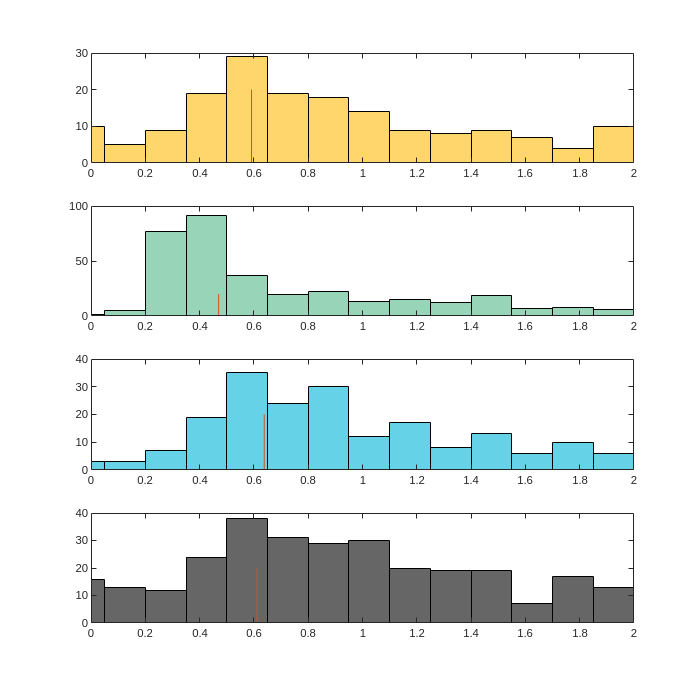

ed = -0.10:0.15:3.5;

colors = ["#ffba08",colcoef(1),colcoef(2),"k"];
clf, hold off
for i = 1:4
    subplot(4,1,i)
    histogram(Latencies(:,i),ed,Facecolor = colors(i))
    hold on
    mL = mean(Latencies(Latencies(:,i) > 0.1 & Latencies(:,i) < 1,i),"omitnan");
    plot([mL,mL],[0,20])
    xlim([0,2])
    hold off
end
%saveas(gcf, "IM_pLat.svg")

## AUROC

i = tv(326); e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
AUROCt = zeros(N,lenwin,3);

for n = 1:N
    for t1 = 1: lenwin
        t = t1 + 325;
        ed = linspace(min([Fr{n}(:,t),Fr{n}(:,tv >= -1 & tv < 0)],[],"all"),max([Fr{n}(:,t),Fr{n}(:,tv >= -1 & tv < 0)],[],"all"),10);
        
        Psrb = histcounts(Fr{n}(:,tv >= -1 & tv < 0), ...
            ed,"Normalization","probability");
        Psr1 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.,t), ...
            ed,"Normalization","probability");
        Psr2 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.,t), ...
            ed,"Normalization","probability");
        Psr3 = histcounts(Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.,t), ...
            ed,"Normalization","probability");
        
        cPsrb = [0,cumsum(Psrb)];
        cPsr1 = [0,cumsum(Psr1)];
        cPsr2 = [0,cumsum(Psr2)];
        cPsr3 = [0,cumsum(Psr3)];

        AUROCt(n,t1,1) = trapz(cPsrb,cPsr1);
        AUROCt(n,t1,2) = trapz(cPsrb,cPsr2);
        AUROCt(n,t1,3) = trapz(cPsrb,cPsr3);
    end
end

Plotting:

for n = 17 %1:N
    figure(n)
    clf, hold off
    plot(tv,AUROCt(n,:,3),"color", "#00b4d8", "LineWidth", 1)
    hold on
    plot(tv,AUROCt(n,:,2),"color", "#52b788", "LineWidth", 1)
    plot(tv,AUROCt(n,:,1),"color", "red", "LineWidth", 1)
    plot(tv,0.5.*ones(length(tv)),"color","k","LineStyle","--")
    legend("Tac - 0", "Aud - 0", "Tac - Aud", 'Location','northwest')
    title(["AUROC", num2str(n)]), xlabel("Time"), ylabel("AUROC")
    xlim([-2,3.5])
end

#### Permutations

AUROCp = zeros(N,lenwin, 3,  1000);

for n = 1:N
    if rem(n, 10) == 0
        n
    end
    Frr = Fr{n}(:,tv >= -1 & tv < 0);
    Frpb = numel(Frr);

    for t1 = 1: lenwin
        t = t1 + 325;
        ed = linspace(min([Fr{n}(:,t), Frr],[],"all"),max([Fr{n}(:,t), Frr],[],"all"),10);

        Frp1 = [Frr(:); Fr{n}(Psyhit{pi(n)}.AmpStim3 ~= 0. & Psyhit{pi(n)}.AudStim3 == 0.,t)];
        Frp2 = [Frr(:); Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 ~= 0.,t)];
        Frp3 = [Frr(:); Fr{n}(Psyhit{pi(n)}.AmpStim3 == 0. & Psyhit{pi(n)}.AudStim3 == 0.,t)];
        
        for p = 1:1000
        
        Frp = Frp1(randperm(length(Frp1)));
        Psrb = histcounts(Frp(1:Frpb), ...
            ed,"Normalization","probability");
        Psr1 = histcounts(Frp(Frpb+1:end), ...
            ed,"Normalization","probability");
        cPsrb = [0,cumsum(Psrb)];
        cPsr1 = [0,cumsum(Psr1)];
        AUROCp(n,t1,1,p) = trapz(cPsrb,cPsr1);

        
        Frp = Frp2(randperm(length(Frp2)));
        Psrb = histcounts(Frp(1:Frpb), ...
            ed,"Normalization","probability");
        Psr1 = histcounts(Frp(Frpb+1:end), ...
            ed,"Normalization","probability");
        cPsrb = [0,cumsum(Psrb)];
        cPsr1 = [0,cumsum(Psr1)];
        AUROCp(n,t1,2,p) = trapz(cPsrb,cPsr1);
        
        Frp = Frp3(randperm(length(Frp3)));
        Psrb = histcounts(Frp(1:Frpb), ...
            ed,"Normalization","probability");
        Psr1 = histcounts(Frp(Frpb+1:end), ...
            ed,"Normalization","probability");
        cPsrb = [0,cumsum(Psrb)];
        cPsr1 = [0,cumsum(Psr1)];
        AUROCp(n,t1,3,p) = trapz(cPsrb,cPsr1);
        
        end
    end
end

n = 10

n = 20

n = 30

n = 40

n = 50

n = 60

n = 70

n = 80

n = 90

n = 100

n = 110

n = 120

n = 130

n = 140

n = 150

n = 160

n = 170

n = 180

n = 190

n = 200

n = 210

n = 220

n = 230

n = 240

n = 250

n = 260

n = 270

n = 280

n = 290

n = 300

n = 310

n = 320

n = 330

n = 340

Significance

P05AUROC = false(N,lenwin, 3);
for n = 1:N
    for a = 1:3
        Pr = sum(abs(AUROCp(n,:, a, :) - 0.5) >= abs(AUROCt(n,:, a) - 0.5), 4)./1000;
        P05 = Pr<0.05;
    
        for t = 1:lenwin - 2 %cluster correction
            if P05(t) == true && P05(t+1) == true && P05(t+2) == true
                P05AUROC(n,[t,t+1,t+2], a) = true;
            end
        end
    end
end

P05AUROC = cat(1,P05AUROC32VPCd, P05AUROC32VPCi, P05AUROC33VPCd);

Plotting:

Population

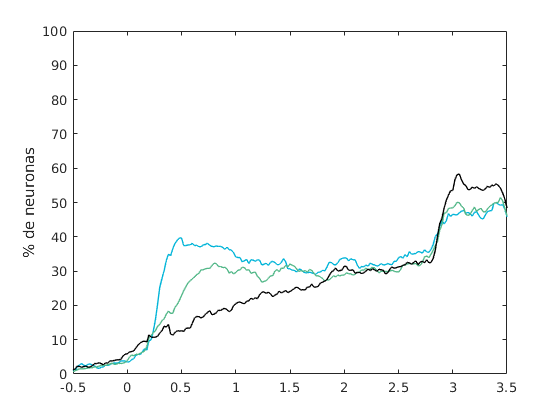

clf, hold off
colcoef = ["#52b788", "#00b4d8", "g", "b"];
plot(tv(wind),sum(P05AUROC(:,:,1))./N * 100,"color",colcoef(2),"LineWidth", 1)
ylabel("% de neuronas")
hold on
plot(tv(wind),sum(P05AUROC(:,:,2))./N * 100,"color",colcoef(1),"LineWidth", 1)
plot(tv(wind),sum(P05AUROC(:,:,3))./N * 100,"color","k","LineWidth", 1)
%legend(["Aud", "Tac", "NoS"], Location="northwest")
%title("% of neurons with significant AUROC"), xlabel("Time")
xlim([-0.5,3.5]), ylim([0,100])
saveas(gcf, "AUROC_all.svg")

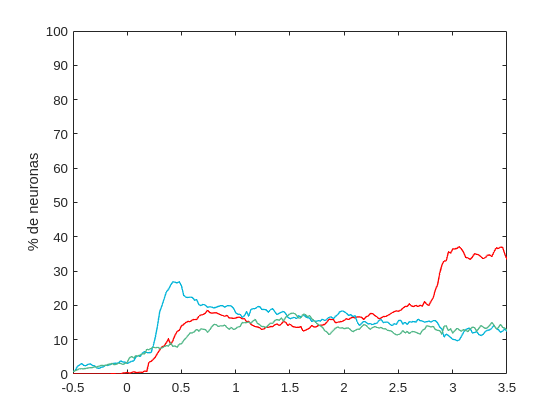

clf, hold off
colcoef = ["#52b788", "#00b4d8", "g", "b"];
plot(tv(wind),sum(P05AUROC(:,:,1) & P05AUROC(:,:,2))./N * 100,"color","r","LineWidth", 1)
ylabel("% de neuronas")
hold on
plot(tv(wind),sum(P05AUROC(:,:,1) & ~P05AUROC(:,:,2))./N * 100,"color",colcoef(2),"LineWidth", 1)
plot(tv(wind),sum(~P05AUROC(:,:,1) & P05AUROC(:,:,2))./N * 100,"color",colcoef(1),"LineWidth", 1)
%legend(["Aud", "Tac", "NoS"], Location="northwest")
%title("% of neurons with significant AUROC"), xlabel("Time")
xlim([-0.5,3.5]), ylim([0,100])

## Variance

Mediat = cell(N,1); Mediab = cell(N,1); Ne = 11;
VarAud = zeros(N,length(tv)); VarTac = zeros(N,length(tv)); Vart = zeros(N,length(tv));
VarEns = zeros(N,length(tv)); VarClass = zeros(N,length(tv)); Var3 = zeros(N,length(tv));

for n = 1 :N
    Mediat{n} = mean(Fr{n});
    
    VarAud(n,:) = sum((meanClass{n}(1:6,:) - Mediat{n}).^2, "omitnan")./6;
    VarTac(n,:) = sum((meanClass{n}([1,7:11],:) - Mediat{n}).^2, "omitnan")./6;
    VarClass(n,:) = sum((meanClass{n} - Mediat{n}).^2, "omitnan")./Ne;
    VarEns(n,:) = mean((Fr{n} - Mediat{n}).^2);
    
    Var3(n,:) = ((mean(meanClass{n}(2:6,:),"omitnan") - Mediat{n}).^2 + (mean(meanClass{n}(7:11,:),"omitnan") - Mediat{n}).^2 + (meanClass{n}(1,:) - Mediat{n}).^2)./3;
    
    Mediab{n} = mean(Fr{n}(:,tv > -2 & tv <= -1),"all","omitnan");
    Vart(n,:) = (Mediat{n}-Mediab{n}).^2;
end

RNN

Mediat = cell(N,1); Mediab = cell(N,1); Ne = 11;
VarAud = zeros(N,length(tv)); VarTac = zeros(N,length(tv)); Vart = zeros(N,length(tv));
VarEns = zeros(N,length(tv)); VarClass = zeros(N,length(tv)); Var3 = zeros(N,length(tv));

for n = 1 :N
    Mediat{n} = mean(Fr{n}, "omitnan");
    
    VarAud(n,:) = sum((meanClass{n}(1:5,:) - Mediat{n}).^2, "omitnan")./6;
    VarTac(n,:) = sum((meanClass{n}([1,6:9],:) - Mediat{n}).^2, "omitnan")./6;
    VarClass(n,:) = sum((meanClass{n} - Mediat{n}).^2, "omitnan")./Ne;
    VarEns(n,:) = mean((Fr{n} - Mediat{n}).^2);

    Var3(n,:) = ((mean(meanClass{n}(2:5,:),"omitnan") - Mediat{n}).^2 + (mean(meanClass{n}(6:9,:),"omitnan") - Mediat{n}).^2 + (meanClass{n}(1,:) - Mediat{n}).^2)./3;
        
    Mediab{n} = mean(Fr{n}(:,tv > -2 & tv <= -1),"all");
    Vart(n,:) = (Mediat{n}-Mediab{n}).^2;
end

for n = 1
    figure(n)
    clf, hold off
    plot(tv, VarAud(n,:),"color", "#00b4d8", "LineWidth", 1)
    hold on
    plot(tv, VarTac(n,:),"color", "#52b788", "LineWidth", 1)
    plot(tv, Vart(n,:),"color", "red", "LineWidth", 1)
    legend("Aud", "Tac", "Temp")
    title(["Variance neuron", num2str(n)]), xlabel("Time"), ylabel("Var")
    xlim([-2,3.5])
end

Poblacional

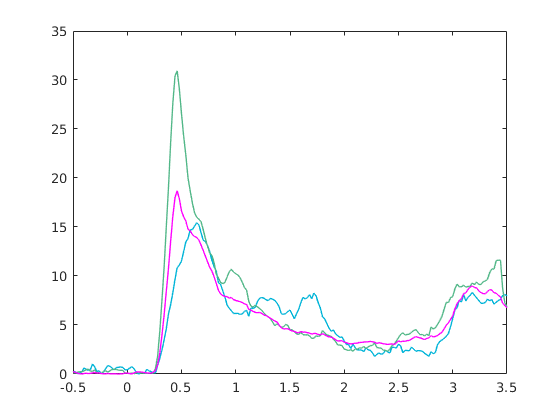

clf, hold off
%figure('Position', get(0,'defaultfigureposition'))
plot(tv, abs(mean(VarAud) - mean(VarAud(:,tv > -1 & tv <= 0),"all")),"color", "#00b4d8", "LineWidth", 1)
hold on
plot(tv, abs(mean(VarTac) - mean(VarTac(:,tv > -1 & tv <= 0),"all")),"color", "#52b788", "LineWidth", 1)
%plot(tv, mean(Vart),"color", "red", "LineWidth", 1)
%plot(tv, mean(VarEns),"color", "#f4a261", "LineWidth", 1)
%plot(tv, abs(mean(VarClass) - mean(VarClass(:,tv > -1 & tv <= 0),"all")),"color", "k", "LineWidth", 1)
plot(tv, abs(mean(Var3) - mean(Var3(:,tv > -1 & tv <= 0),"all")),"color", "m", "LineWidth", 1)
%legend("Aud", "Tac","Mod","Location","northwest")
%title("Population Variance")
%xlabel("Time"), ylabel("Var")
xlim([-0.5,3.5]) %[-1,2]
%ylim([0,20])
saveas(gcf, "Var3_all.svg")

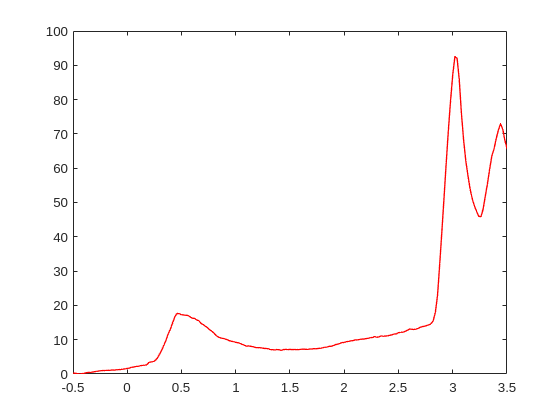

clf, hold off
plot(tv, abs(mean(Vart) - mean(Vart(:,tv > -1 & tv <= 0),"all")),"color", "red", "LineWidth", 1)
xlim([-0.5,3.5])
saveas(gcf, "Vart_all.svg")

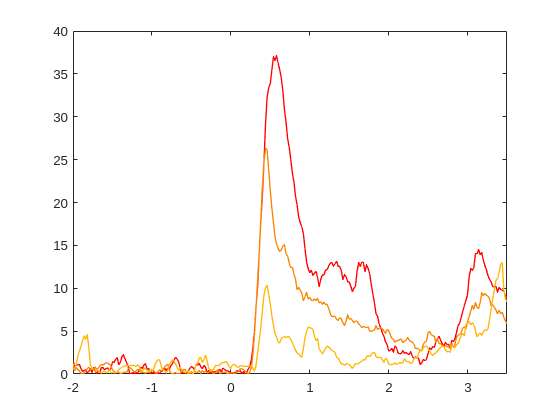

clf, hold off
plot(tv, abs(mean(VarClass32d) - mean(VarClass32d(:,tv > -1 & tv <= 0),"all")),"color", "red", "LineWidth", 1)
hold on
plot(tv, abs(mean(VarClass32i) - mean(VarClass32i(:,tv > -1 & tv <= 0),"all")),"color", "#fb8500", "LineWidth", 1)
plot(tv, abs(mean(VarClass) - mean(VarClass(:,tv > -1 & tv <= 0),"all")),"color", "#ffb703", "LineWidth", 1)
xlim([-2,3.5])
%legend("32d","32i","33d","Location","northwest")
saveas(gcf, "VarClass.svg")

## PCA

%Stimulus : i = tv(351); e = tv(376);. Delay : i = tv(401); e = tv(476);. All : i = tv(351); e = tv(526);
%RNN tv(166); e = tv(239);
i = tv(351); e = tv(526);
 
Covar = zeros(N,N); 
Mt = zeros(N,1);
for n = 1:N
    Mt(n) = mean(Mediat{n}(tv >= 0 & tv < 3.5)); %mean(Mediat{n}(tv >= i & tv < e)); %Mediab{n}; %
end

%equally weighted
for n1 = 1:N
    for n2 = n1:N
       Covar(n1,n2) = mean((meanClass{n1}(:,tv >= i & tv < e)-Mt(n1)).*(meanClass{n2}(:,tv >= i & tv < e)-Mt(n2)),"all","omitnan");
       Covar(n2,n1) = Covar(n1,n2);
    end
end

%weighted by prob.
for n1 = 1:N
    for n2 = n1:N
       Covar(n1,n2) = mean((meanClass{n1}(1,tv >= i & tv < e)-Mt(n1)).*(meanClass{n2}(1,tv >= i & tv < e)-Mt(n2)),"omitnan").*(1/3);
       Covar(n1,n2) = Covar(n1,n2) + sum(mean((meanClass{n1}(2:end,tv >= i & tv < e)-Mt(n1)).*(meanClass{n2}(2:end,tv >= i & tv < e)-Mt(n2)),2,"omitnan"),"omitnan")*(1/15);
       Covar(n2,n1) = Covar(n1,n2);
    end
end

%Only no Stim
for n1 = 1:N
    mean_NS_n1 = mean(Mediat{n1}(tv >= -1 & tv < 0)); %Mt(n1); %mean(meanClass{n1}(1,tv >= i & tv < e),"omitnan");
    for n2 = n1:N
       mean_NS_n2 = mean(Mediat{n2}(tv >= -1 & tv < 0)); %Mt(n2); %mean(meanClass{n1}(1,tv >= i & tv < e),"omitnan");
       Covar(n1,n2) = mean((meanClass{n1}(1,tv >= i & tv < e)-mean_NS_n1).* ...
           (meanClass{n2}(1,tv >= i & tv < e)-mean_NS_n2),"omitnan");
       Covar(n2,n1) = Covar(n1,n2);
    end
end

PCA

Nc = 10;
[Eigv, Eiga] = eigs(Covar,Nc);
Eiga = diag(Eiga);

%sum(abs(Eiga))./sum(diag(Covar))
%Eigv_list = cell(1,4);
%Eigv_list{4} = Eigv;

Explained Variance

abs(Eiga)./sum(diag(Covar))

ans =     0.1780
    0.1213
    0.1083
    0.0611
    0.0520
    0.0377
    0.0291
    0.0213
    0.0196
    0.0163


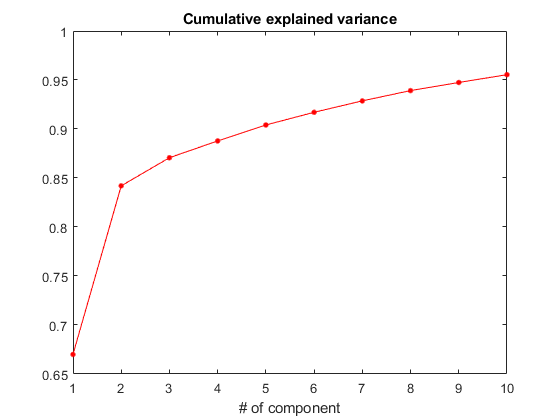

clf, hold off
plot(1:Nc,cumsum(abs(Eiga))./sum(diag(Covar)),"Color","r","Marker",".",MarkerSize=12)
xlim([1,Nc]), title("Cumulative explained variance"), xlabel("# of component")

clf, hold off
for c = 1:6
    subplot(3,2,c)
    histogram(Eigv(:,c),"FaceColor","m")
    title(["Comp ", num2str(c)])
    xlim([-0.3,0.3])
end
sgtitle("Distribution of first 6 PCs")

Weights correlation

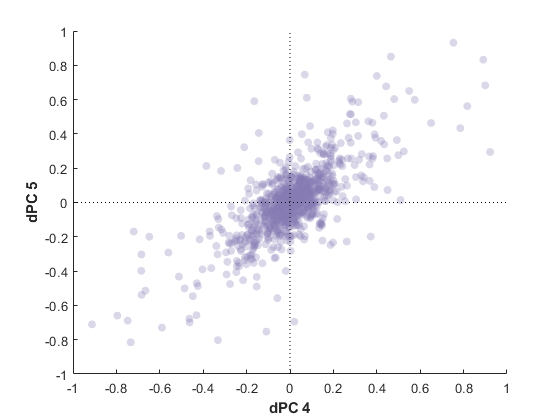

x = W(:,4); y = W(:,5);
lim3 = 1; lim2 = 1;
clf, hold off
scatter(x, y, "MarkerFaceColor", "#857ab2", "MarkerFaceAlpha", 0.3,"MarkerEdgeColor","none")
hold on
plot([-lim3,lim3],[0,0],"Color","k","LineStyle",":")
plot([0,0],[-lim2,lim2],"Color","k","LineStyle",":")
xlim([-lim3,lim3]), ylim([-lim2,lim2])
ylabel("dPC 5",FontWeight="bold")
xlabel("dPC 4",FontWeight="bold")

%saveas(gcf, "corrdPC45.svg")

### PCA noise

Noise Fr

Frn = cell(N,1);
ClassN = cell(N,1);

for n = 1:N
    ClassN{n} = ones(length(Fr{n}(:,1)),1);
    for e = 1:length(Fr{n}(:,1))
        for c = 1:C
            if c == 10
                if (Psyhit{pi(n)}.AmpStim3(e) == classes(c,1) || Psyhit{pi(n)}.AmpStim3(e) == 16.) && Psyhit{pi(n)}.AudStim3(e) == classes(c,2)
                    ClassN{n}(e) = c;
                end
            elseif c == 11
                if (Psyhit{pi(n)}.AmpStim3(e) == classes(c,1) || Psyhit{pi(n)}.AmpStim3(e) == 20.) && Psyhit{pi(n)}.AudStim3(e) == classes(c,2)
                    ClassN{n}(e) = c;
                end
            else
                if Psyhit{pi(n)}.AmpStim3(e) == classes(c,1) && Psyhit{pi(n)}.AudStim3(e) == classes(c,2)
                    ClassN{n}(e) = c;
                end
            end
        end
    end
    Frn{n} = Fr{n}-meanClass{n}(ClassN{n},:);
end

i = 0

e = 3.5000

Covar noise

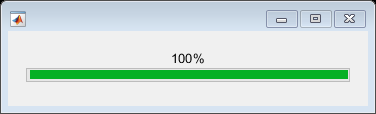

Covarn = zeros(N,N,100); 

wb = waitbar(0);

for p = 1:100
    waitbar(p/100, wb, strcat(num2str(p),"%"))
    for n1 = 1:N
        for n2 = n1:N
           cv = 0;
           for e1 = randperm(length(Fr{n1}(:,1)),10)%length(Fr{n1}(:,1))
               for e2 = randperm(length(Fr{n2}(:,1)),10)%length(Fr{n2}(:,1))
                cv = cv + mean((Frn{n1}(e1,tv >= i & tv < e)).*(Frn{n2}(e2,tv >= i & tv < e)),"omitnan")/(length(Fr{n1}(:,1))*length(Fr{n2}(:,1))); 
               end
           end
           Covarn(n1,n2,p) = cv;
           Covarn(n2,n1,p) = Covar(n1,n2);
        end
    end
end

PCA

Eigaps = zeros(100,Nc);
Vartotp = zeros(100,1);

for p = 1:100
    [~, Eigap] = eigs(squeeze(Covarn(:,:,p)),Nc);
    Eigaps(p,:) = diag(Eigap);
    Vartotp(p) = sum(diag(squeeze(Covarn(:,:,p))));
end

Ploting

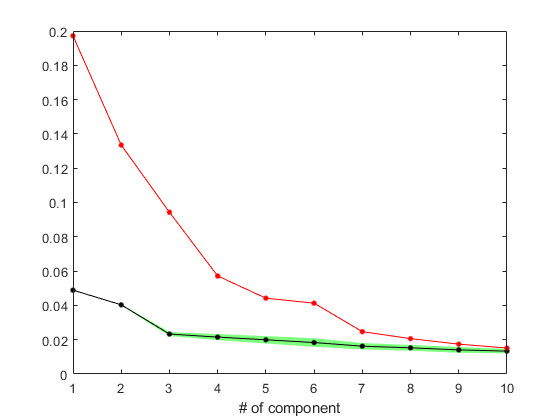

clf, hold off
y = mean(abs(Eigaps)./Vartotp);
s = std(abs(Eigaps)./Vartotp);
fill([1:Nc, fliplr(1:Nc)], [y + 2*s, fliplr(y - 2*s)], 'g', Facealpha = 0.5, edgecolor="none")
hold on
plot(1:Nc,y,"Color","k","Marker",".",MarkerSize=12)
plot(1:Nc,abs(Eiga)./sum(diag(Covar)),"Color","r","Marker",".",MarkerSize=12)
xlim([1,Nc]), xlabel("# of component")
saveas(gcf, "VarPCA_eq.svg")

%PCAn_del = {Eigaps, Vartotp, Covarn};

### Proyection in coefficients

nPc = 10; %10;
proyecPC = zeros(nPc, C + 2, lentv);

% NoS diff
%Eigv = meanClassvec(:, 1, tv == e) - meanClassvec(:, 1, tv == i);
%Eigv = Eigv / norm(Eigv);

for c = 1:nPc    
    for t = 1:lentv
        for s = 1:C
            M = meanClassvec(:, s, t);
            M(isnan(M)) = 0;
            proyecPC(c, s, t) = M'*Eigv(:,c);
        end
        proyecPC(c, end - 1, t) = mean(meanClassvec(:, 3:6, t), 2, "omitnan")'*Eigv(:,c); %All Aud
        proyecPC(c, end, t) = mean(meanClassvec(:, 7:end, t), 2, "omitnan")'*Eigv(:,c); %All Tac
    end
end

RNN

nPc = 6;
proyecPC = zeros(nPc, C + 2, lentv);

meanClassvec = zeros(N,C,lentv);

for n = 1: N
    meanClassvec(n,:,:) = meanClass{n}(:,:);
end

for c = 1:nPc    
    for t = 1:lentv
        for s = 1:C
            proyecPC(c, s, t) = meanClassvec(:, s, t)'*Eigv(:,c);
        end
        proyecPC(c, end - 1, t) = mean(meanClassvec(:, 2:5, t), 2, "omitnan")'*Eigv(:,c); %All Aud
        proyecPC(c, end, t) = mean(meanClassvec(:, 6:end, t), 2, "omitnan")'*Eigv(:,c); %All Tac
    end
end


proyecPC = proyecPC([4,5,8],:,:); %dPCA

Ploting 3D

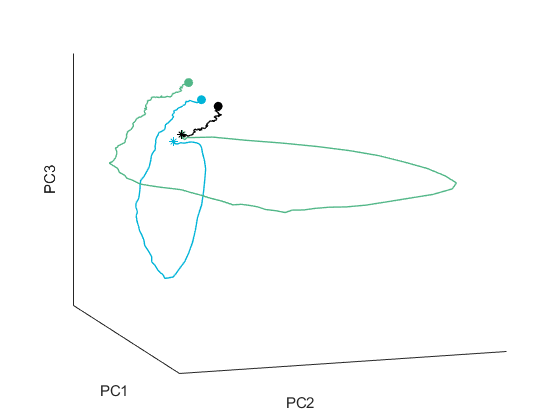

i = tv(351); e = tv(476);
wind = tv >= i & tv <= e;
rgb = [0, 0, 1; 0, 180, 216; 82, 183, 136]./ 255; %1, ["k", colcoef(1),colcoef(2)],
colcoef = ["#52b788", "#00b4d8", "g", "b"];

clf, hold off

plot3(squeeze(proyecPC(1,1,wind)),squeeze(proyecPC(2,1,wind)),squeeze(proyecPC(3,1,wind)),"color","k","LineWidth",1)
hold on
plot3(squeeze(proyecPC(1,end - 1,wind)),squeeze(proyecPC(2,end - 1,wind)),squeeze(proyecPC(3,end - 1,wind)),"color",colcoef(2),"LineWidth",1)
plot3(squeeze(proyecPC(1,end,wind)),squeeze(proyecPC(2,end,wind)),squeeze(proyecPC(3,end,wind)),"color",colcoef(1),"LineWidth",1)
xlabel("PC1"), ylabel("PC2"), zlabel("PC3"), 


scatter3([proyecPC(1,1,tv == i), proyecPC(1,end - 1,tv == i), proyecPC(1,end,tv == i)], ...
    [proyecPC(2,1,tv == i), proyecPC(2,end - 1,tv == i), proyecPC(2,end,tv == i)], ...
    [proyecPC(3,1,tv == i), proyecPC(3,end-1,tv == i), proyecPC(3,end,tv == i)], [], rgb, Marker="*")
scatter3([proyecPC(1,1,tv == e), proyecPC(1,end - 1,tv == e), proyecPC(1,end,tv == e)], ...
    [proyecPC(2,1,tv == e), proyecPC(2,end - 1,tv == e), proyecPC(2,end,tv == e)], ...
    [proyecPC(3,1,tv == e), proyecPC(3,end-1,tv == e), proyecPC(3,end,tv == e)], [], rgb, Marker="o",MarkerFaceColor="flat")

task_points = 0;
if task_points == 1
i = tv(376);%tv(166+25);
scatter3([proyecPC(1,1,tv == i), proyecPC(1,end - 1,tv == i), proyecPC(1,end,tv == i)], ...
     [proyecPC(2,1,tv == i), proyecPC(2,end - 1,tv == i), proyecPC(2,end,tv == i)], ...
     [proyecPC(3,1,tv == i), proyecPC(3,end-1,tv == i), proyecPC(3,end,tv == i)], [], rgb, Marker="^",MarkerFaceColor="flat")

end
% for n = 1:6
%     scatter3([sols(:,n)'*Eigv(:,1)], ...
%         [sols(:,n)'*Eigv(:,2)], ...
%         [sols(:,n)'*Eigv(:,3)], [], [216, 17, 89]./ 255, Marker="+")
% end
set(gca,'XTick',[]), set(gca,'YTick',[]), set(gca,'ZTick',[])

grid off

view([72 16])

%title("0 - 0.5")
%saveas(gcf, "PCA_eq_all.svg")

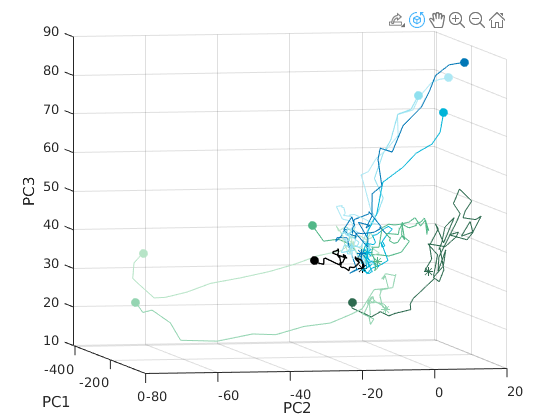

i = tv(326); e = tv(376); %0.6 = tv(381), 3.5 = tv(526)
wind = tv >= i & tv <= e;
rgb = [0, 0, 0; 3, 4, 94; 0, 119, 182;0, 180, 216;144, 224, 239;173, 232, 244;8, 28, 21;45, 106, 79;82, 183, 136;149, 213, 178;183, 228, 199]./ 255; %1, ["k", colcoef(1),colcoef(2)],
clf, hold off
hold on
for c = 3:6 %AUD no lower class
    plot3(squeeze(proyecPC(1,c,wind)),squeeze(proyecPC(2,c,wind)),squeeze(proyecPC(3,c,wind)),"color",colaud(c-1))
    scatter3(proyecPC(1,c,tv == i), proyecPC(2, c,tv == i), proyecPC(3, c,tv == i), [], rgb(c,:), Marker="*")
    scatter3(proyecPC(1,c,tv == e), proyecPC(2, c,tv == e), proyecPC(3, c,tv == e), [], rgb(c,:), Marker="o",MarkerFaceColor="flat")
end
for c = 8:11 %TAC no lower class
    plot3(squeeze(proyecPC(1,c,wind)),squeeze(proyecPC(2,c,wind)),squeeze(proyecPC(3,c,wind)),"color",coltac(c-6))
    scatter3(proyecPC(1,c,tv == i), proyecPC(2, c,tv == i), proyecPC(3, c,tv == i), [], rgb(c,:), Marker="*")
    scatter3(proyecPC(1,c,tv == e), proyecPC(2, c,tv == e), proyecPC(3, c,tv == e), [], rgb(c,:), Marker="o",MarkerFaceColor="flat")
end
plot3(squeeze(proyecPC(1,1,wind)),squeeze(proyecPC(2,1,wind)),squeeze(proyecPC(3,1,wind)),"color","k","LineWidth",1)
scatter3(proyecPC(1,1,tv == i), proyecPC(2, 1,tv == i), proyecPC(3, 1,tv == i), [], rgb(1,:), Marker="*")
scatter3(proyecPC(1,1,tv == e), proyecPC(2, 1,tv == e), proyecPC(3, 1,tv == e), [], rgb(1,:), Marker="o",MarkerFaceColor="flat")

xlabel("PC1"), ylabel("PC2"), zlabel("PC3"), 

grid on


%view([62.3 43.8])

Ploting individual PC

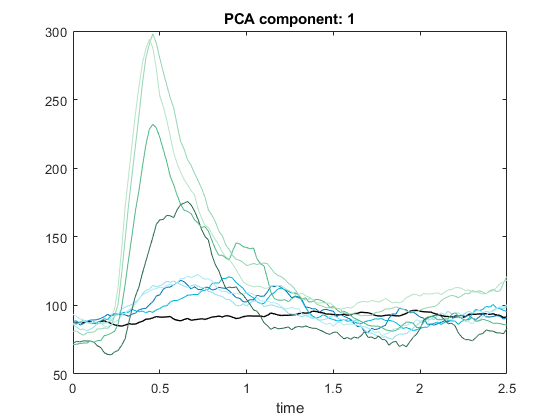

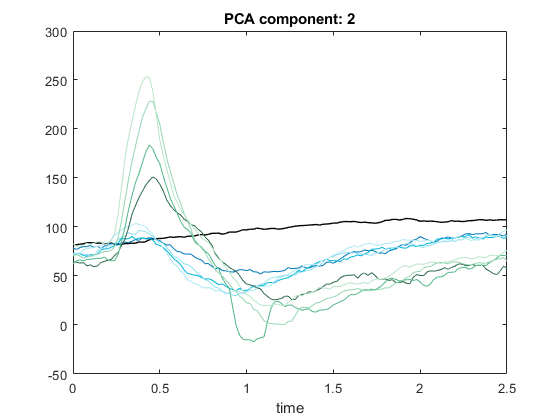

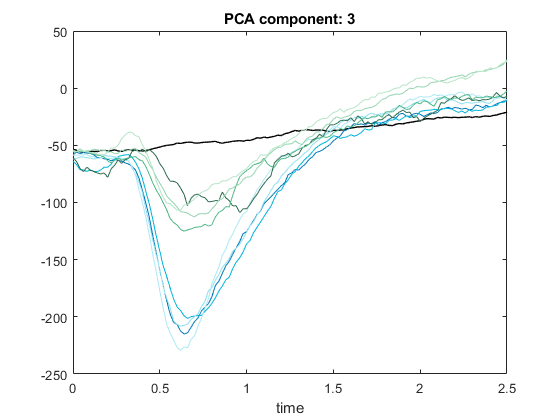

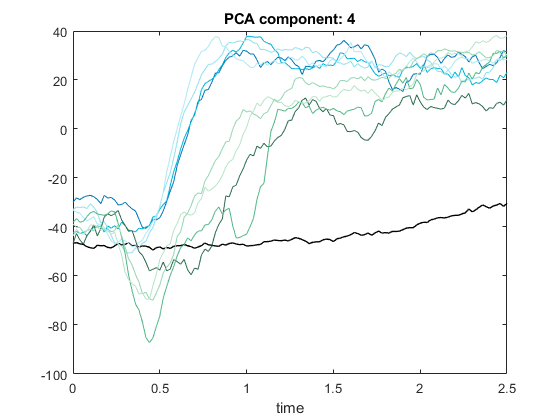

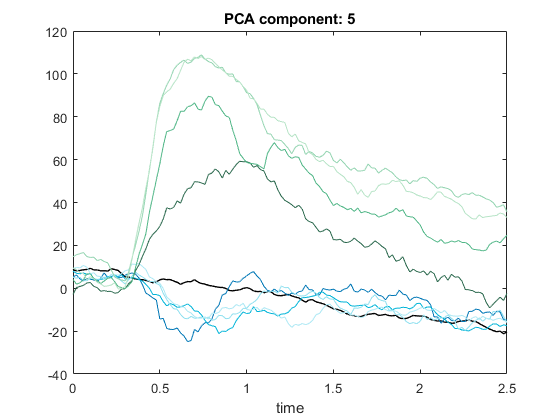

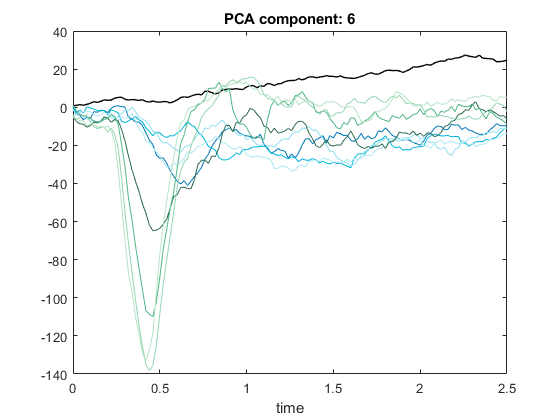

for p = 1:6%nPc
    figure(p)
    clf, hold off
    plot(tv(wind),squeeze(proyecPC(p,1,wind)),"color","k","LineWidth",1)
    hold on
    for c = 3:6 %AUD no lower class
        plot(tv(wind),squeeze(proyecPC(p,c,wind)),"color",colaud(c-1))
    end
    for c = 8:11 %TAC no lower class
        plot(tv(wind),squeeze(proyecPC(p,c,wind)),"color",coltac(c-6))
    end
    %plot(tv(wind),squeeze(proyecPC(p,end - 1,wind)),"color",colcoef(2),"LineWidth",1)
    %plot(tv(wind),squeeze(proyecPC(p,end,wind)),"color",colcoef(1),"LineWidth",1)
    
    xlabel("time")
    title(strcat("PCA component: ", num2str(p)))
    %saveas(gcf, strcat("PCA_bas_eq_", num2str(p),".svg"))
end

2d plot

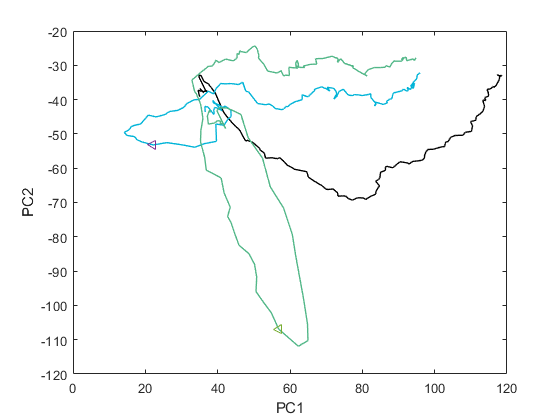

clf, hold off
plot(squeeze(proyecPC(1,1,wind)),squeeze(proyecPC(2,1,wind)),"color","k","LineWidth",1)
hold on
plot(squeeze(proyecPC(1,end - 1,wind)),squeeze(proyecPC(2,end - 1,wind)),"color",colcoef(2),"LineWidth",1)
plot(squeeze(proyecPC(1,end,wind)),squeeze(proyecPC(2,end,wind)),"color",colcoef(1),"LineWidth",1)
scatter(squeeze(proyecPC(1,end - 1,tv == tv(376))),squeeze(proyecPC(2,end - 1,tv == tv(376))),"Marker","<")
scatter(squeeze(proyecPC(1,end,tv == tv(376))),squeeze(proyecPC(2,end,tv == tv(376))),"Marker","<")
xlabel("PC1")
ylabel("PC2")

saveas(gcf, strcat("PCA_no_stim2d.svg"))

### Exp. variance by time

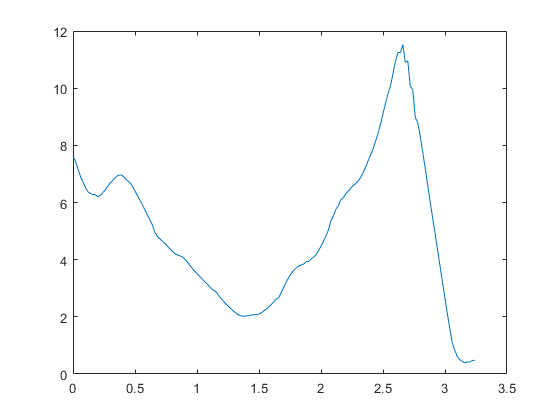

i = 0; f = 3.25;
lenwin  = sum(tv >= i & tv < f);
Npc = 3;
Explained_var = zeros(lenwin,1);
Vartott = zeros(lenwin,1);

for t = 1:lenwin
    Vartott(t) = sum(diag(squeeze(Covart(:,:,t))));
    for c = 1:Npc
        Explained_var(t) = Explained_var(t) + Eigv(:,c).'*squeeze(Covart(:,:,t))*Eigv(:,c);
    end
end


clf, hold off
plot(tv(tv >= i & tv < f), Explained_var ./ Vartott * 100)
hold on

%saveas(gcf, "VarAx2.svg")

### Trayoctorys' Speed

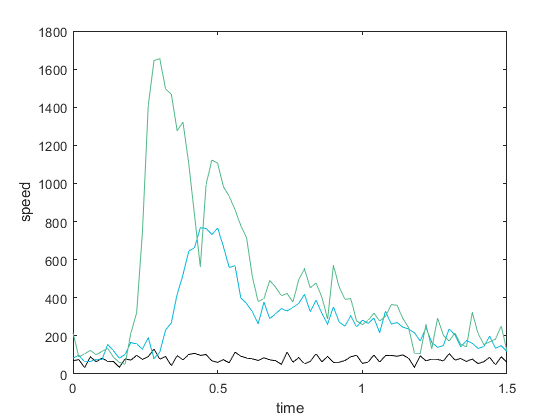

nPc = 6;
speed = zeros(nPc, C + 2, lentv);
for t = 1:lentv-1
    for c = 1:C+2
        speed(c,t) = sqrt(sum((proyecPC(1:nPc,c,t+1) - proyecPC(1:nPc,c,t)).^2));
    end
end
speed = speed/pas;

i = tv(351); e = tv(526);
wind = tv >= i & tv <= e;
clf, hold off
plot(tv(wind),speed(1,wind),"color","k","LineWidth",1)
hold on
% for c = 3:6 %AUD no lower class
%     plot(tv(wind),speed(c,wind),"color",colaud(c-1))
% end
% for c = 8:11 %TAC no lower class
%     plot(tv(wind),speed(c,wind),"color",coltac(c-6))
% end
plot(tv(wind),speed(end - 1,wind),"color",colcoef(2),"LineWidth",1)
plot(tv(wind),speed(end,wind),"color",colcoef(1),"LineWidth",1)
xlim([0,1.5])
xlabel("time")
ylabel("speed")
saveas(gcf, strcat("speed_avg.svg"))

## **dPCA**

firingRatesAverage: N x S x D x T

N is the number of neurons

S is the number of stimuli conditions (F1 frequencies in Romo's task)

D is the number of decisions (D=2)

T is the number of time-points (note that all the trials should have the

same length in time!)

meanClassvec = N x C x lentv

W is the decoder, V is the encoder (ordered by explained variance),

whichMarg is an array that tells you which component comes from which

marginalization



% N Amp Bot T (Doesn't work, singular matrix)
% for c = 1:5 %No stimulus
%     firingRatesAverage(:,c,1,:) = meanClassvec(:,1,tv >= i & tv <= e);
% end
% 
% for c = 1:5 %Tac
%     firingRatesAverage(:,c,2,:) = meanClassvec(:,c+1,tv >= i & tv <= e);
% end
% 
% for c = 1:5 %Aud
%     firingRatesAverage(:,c,3,:) = meanClassvec(:,c+6,tv >= i & tv <= e);
% end
% combinedParams = {{1, [1 3]}, {2, [2 3]}, {3}, {[1 2], [1 2 3]}};

% N Bot T
% firingRatesAverage = zeros(N,3,lenwin);
% margNames = ["Boton", "Time"];
% nPc = 10;
% 
% i = tv(326); e = tv(526);
% wind = tv >= i & tv <= e;
% firingRatesAverage(:,1,:) = meanClassvec(:,1,wind);
% firingRatesAverage(:,2,:) = mean(meanClassvec(:, 3:6, wind), 2, "omitnan");
% firingRatesAverage(:,3,:) = mean(meanClassvec(:, 7:end, wind), 2, "omitnan");
% 
% combinedParams = {{1, [1 2]}, {2}};
% 
% [W,V,whichMarg] = dpca(firingRatesAverage, nPc, ...
%     'combinedParams', combinedParams);

i = tv(326); e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);

% N Class (no low class) T
firingRatesAverage = zeros(N,C-2-1,lenwin);
margNames = ["Class", "Time"];
nPc = 10;

%firingRatesAverage(:,1,:) = meanClassvec(:,1,wind);
for c = 3:6 %AUD no lower class
    firingRatesAverage(:,c-1-1,:) = meanClassvec(:,c,wind);
end
for c = 8:11 %TAC no lower class
    firingRatesAverage(:,c-2-1,:) = meanClassvec(:,c,wind);
end

%eliminate nans
Fnans = [0;0];
for n = 1:N
    for c = C-2-1:-1:1
        if isnan(firingRatesAverage(n,c,1))
            Fnans = [Fnans,[n;c]];
            if c < C-2
                firingRatesAverage(n,c,:) = firingRatesAverage(n,c+1,:);
            else
                firingRatesAverage(n,c,:) = firingRatesAverage(n,c-1,:);
            end
        end
    end
end 

combinedParams = {{1, [1 2]}, {2}};


[W,V,whichMarg] = dpca(firingRatesAverage, nPc, ...
    'combinedParams', combinedParams);

Matrix close to singular, using tiny regularization, lambda = 1e-10
Matrix close to singular, using tiny regularization, lambda = 1e-10


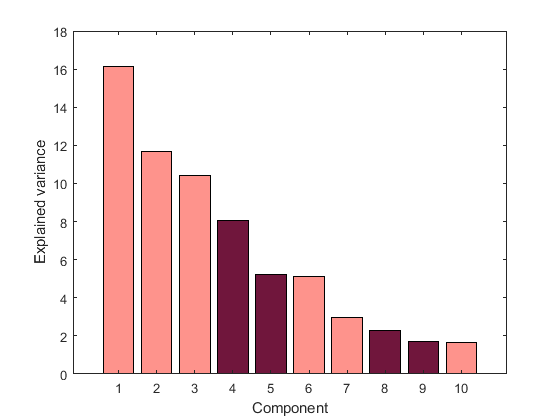

explVar = dpca_explainedVariance(firingRatesAverage, W, V, ...
     'combinedParams', combinedParams);

colvar = [112, 22, 60;254, 147, 140]./255; %93, 87, 107

clf, hold off
b = bar(explVar.componentVar);
b.FaceColor = 'flat';
for c = 1:nPc
    b.CData(c,:) = colvar(whichMarg(c),:);
end
ylabel("Explained variance")
xlabel("Component")

%saveas(gcf, "dPCA_varNoNull.svg")

Correlacion

c = corrcoef(Eigv(:,1),Eigv(:,4),Rows="pairwise");
c(1,2)

ans = -8.9667e-04

x = W(:,4) / norm(W(:,4));
y = W(:,5) / norm(W(:,5));
x.' * y

ans = 0.7707

### Proyection in coefficients

proyecPC = zeros(nPc, C + 2, lentv);

for c = 1:nPc    
    for t = 1:lentv
        for s = 1:C
            M = meanClassvec(:, s, t);
            M(isnan(M)) = 0;
            proyecPC(c, s, t) = M'*W(:,c);
        end
        proyecPC(c, end - 1, t) = mean(meanClassvec(:, 3:6, t), 2, "omitnan")'*W(:,c); %All Aud
        proyecPC(c, end, t) = mean(meanClassvec(:, 7:end, t), 2, "omitnan")'*W(:,c); %All Tac
    end
end

Ploting

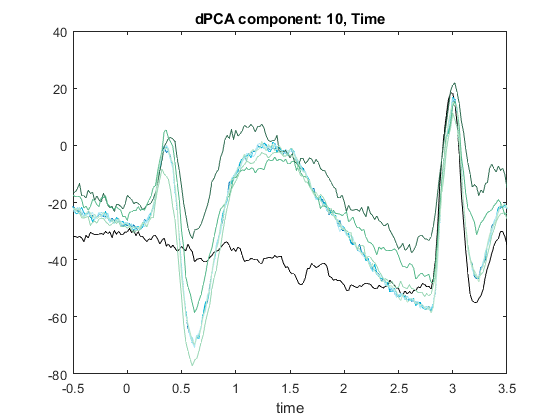

for p = 1:10%[4,5,8]%nPc
    %figure(p)
    clf, hold off
    plot(tv(wind),squeeze(proyecPC(p,1,wind)),"color","k","LineWidth",1)
    hold on
    
    for c = 3:6 %AUD no lower class
        plot(tv(wind),squeeze(proyecPC(p,c,wind)),"color",colaud(c-1))
    end
    for c = 8:11 %TAC no lower class
        plot(tv(wind),squeeze(proyecPC(p,c,wind)),"color",coltac(c-6))
    end
%     plot(tv(wind),squeeze(proyecPC(p,end - 1,wind)),"color",colcoef(2),"LineWidth",1)
%     plot(tv(wind),squeeze(proyecPC(p,end,wind)),"color",colcoef(1),"LineWidth",1)
    
    xlabel("time")
    title(strcat("dPCA component: ", num2str(p), ", ", margNames(whichMarg(p))))
    saveas(gcf, strcat("dPCA component ", num2str(p),".svg"))

end

%dPCA_boton = {W, V, whichMarg};
%dPCA_class = {W, V, whichMarg};
W = dPCA_boton{1};
V = dPCA_boton{2};
whichMarg = dPCA_boton{3};


Cosine similarity

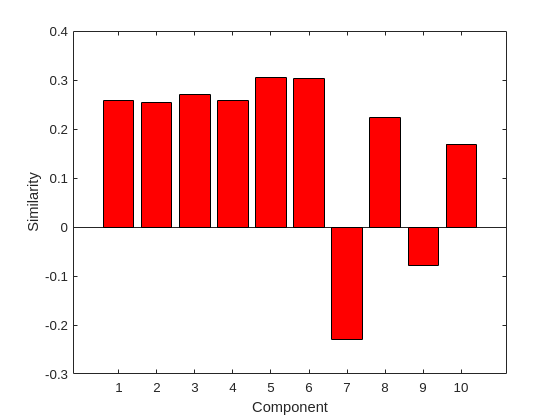

CSdPCA = zeros(1,nPc);
for p = 1:nPc
    CSdPCA(p) = dPCA_boton{1}(:,p)'*dPCA_class{1}(:,p) ./ (norm(dPCA_boton{1}(:,p))*norm(dPCA_class{1}(:,p)));
end

clf, hold off
bar(CSdPCA,"FaceColor","r")
ylabel("Similarity")
xlabel("Component")

## **Population similarity**

### **Cosine similarity PCA**

i = 0; f = 3.25; % f = 2.48
lenwin  = sum(tv >= i & tv < f);
Covart = zeros(N,N,lenwin); 
pas = 0.02;
winwidth = 0.24; %0.5

for t = 1:lenwin
    for n1 = 1:N
        for n2 = n1:N
           Covart(n1,n2,t) = mean((meanClass{n1}(:,tv >= i + pas*t & tv < i + winwidth + pas*t)-Mt(n1)).*(meanClass{n2}(:,tv >= i + pas*t & tv < i + winwidth + pas*t)-Mt(n2)),"all","omitnan");
           Covart(n2,n1,t) = Covart(n1,n2,t);
        end
    end
end

PCA

% Eigvt = zeros(N,lenwin);
% for t = 1:lenwin
%     [Eigvt(:,t), ~] = eigs(squeeze(Covart(:,:,t)),1);
% end

Eigvt3 = zeros(N,lenwin,3);
for t = 1:lenwin
    [Eigvt3(:,t,:), ~] = eigs(squeeze(Covart(:,:,t)),3);
end


Cossim = zeros(lenwin, lenwin);
for t1 = 1:lenwin
    for t2 = t1:lenwin
       Cossim(t1,t2) = Eigvt(:,t1)'*Eigvt(:,t2) ./ (norm(Eigvt(:,t1))*norm(Eigvt(:,t2)));
       Cossim(t2,t1) = Cossim(t1,t2);
    end
end

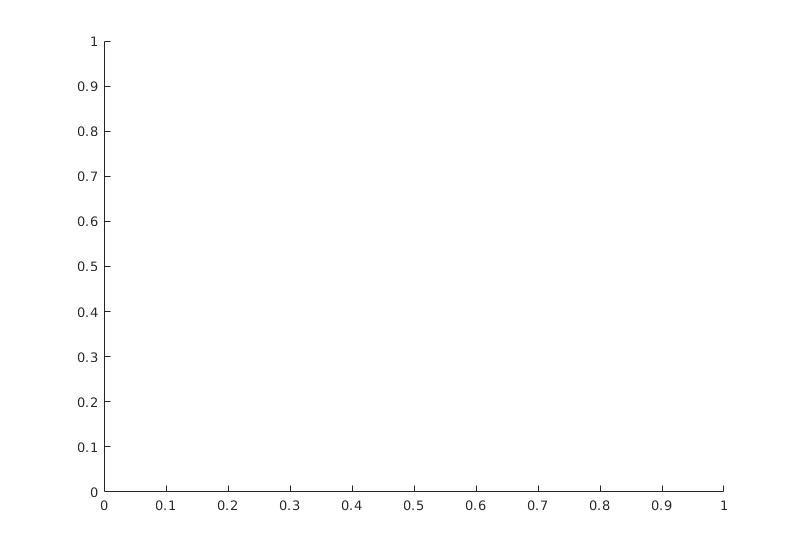

clf, hold off

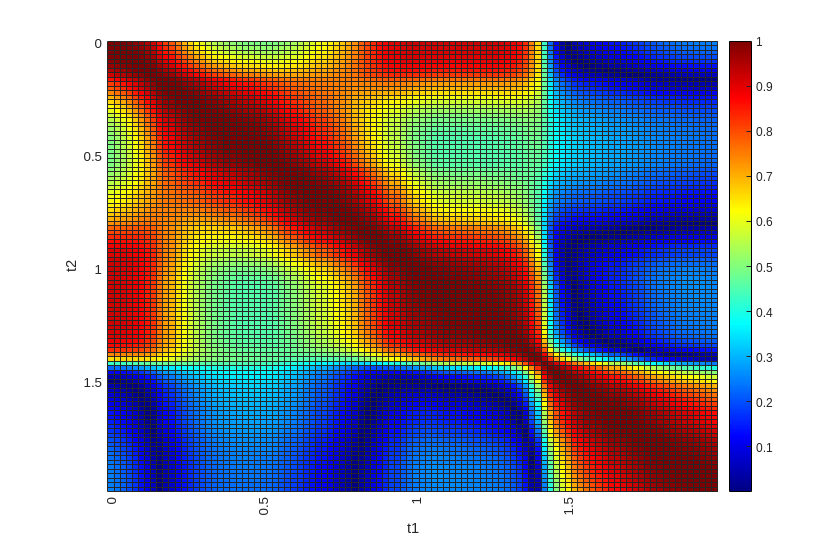

figure('Renderer', 'painters', 'Position', [10 10 900 600])
heatmap(abs(Cossim(1:100,1:100)),"CellLabelColor",'none')
%ticks = [0,repmat(nan,1,24),0.5,repmat(nan,1,24),1,repmat(nan,1,24),1.5,repmat(nan,1,24),2,repmat(nan,1,24),2.5,repmat(nan,1,24),3,repmat(nan,1,12)];
ticks = [0,nan(1,24),0.5,nan(1,24),1,nan(1,24),1.5,nan(1,24)];%,repmat(nan,1,23)];
ax = gca;
ax.XDisplayLabels = ticks;
ax.YDisplayLabels = ticks;
colormap jet
colorbar
xlabel("t1"), ylabel("t2")
%title("Cosine similarity PC1")
saveas(gcf, "CosSimVPC.svg")

### **Cosine similarity States**

i = tv(141); ii = 140; e = tv(290); %i = tv(326); ii = 326; e = tv(526);
wind = tv >= i & tv <= e;
lenwin = sum(wind);
CosStates = zeros(lenwin,lenwin, 4); %Null, Aud, Tac, All
States = [1,5,9]; %[1,6,11];

for t1 = 1:lenwin
    for t2 = t1:lenwin
        for s = 1:3
            a = meanClassvec(:,States(s),t1 + ii);
            a(isnan(a)) = 0;
            b = meanClassvec(:,States(s),t2 + ii);
            b(isnan(b)) = 0;
            CosStates(t1,t2,s) = a'*b./ (norm(a)*norm(b));
        end
        a = reshape(meanClassvec(:,:,t1 + ii),N*C,[]);
        a(isnan(a)) = 0;
        b = reshape(meanClassvec(:,:,t2 + ii),N*C,[]);
        b(isnan(b)) = 0;
        CosStates(t1,t2,4) = a'*b./ (norm(a)*norm(b));
        CosStates(t2,t1,:) = CosStates(t1,t2,:);
    end
end

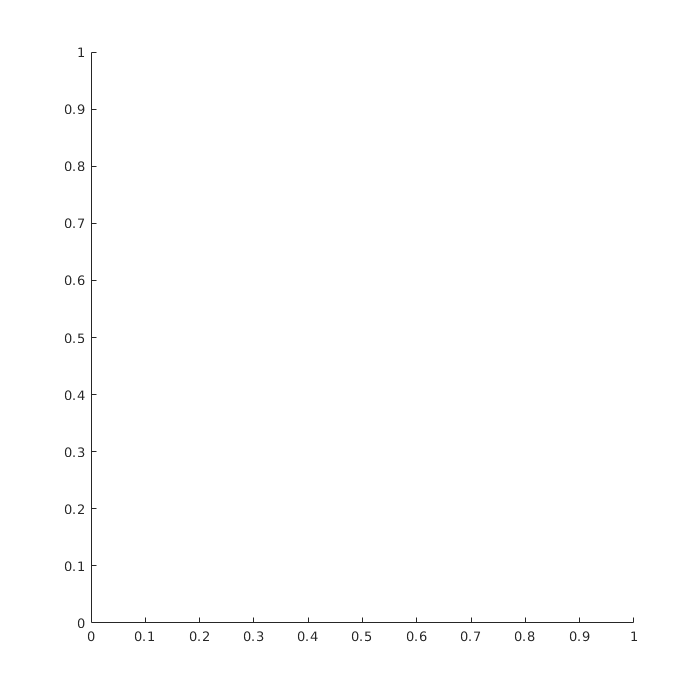

clf, hold off

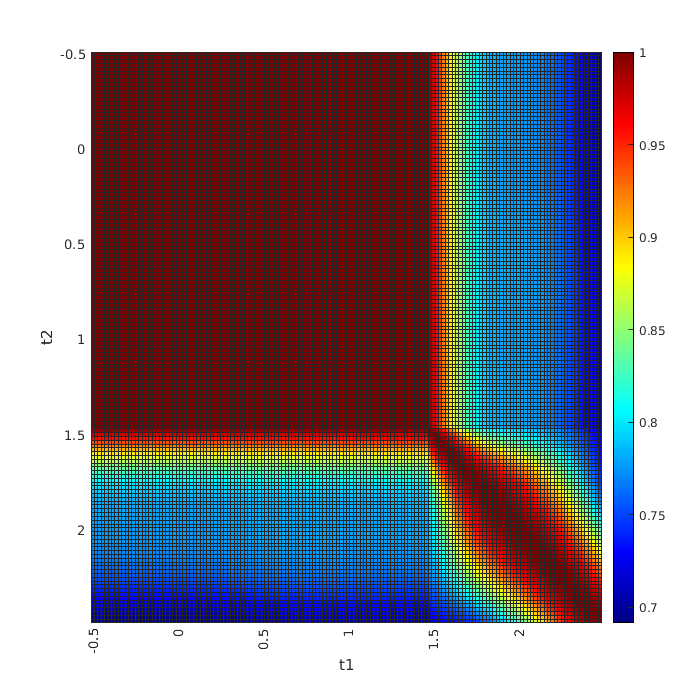

figure('Renderer', 'painters', 'Position', [10 10 700 700])
heatmap(abs(squeeze(CosStates(:,:,1))),"CellLabelColor",'none')
%ticks = [-0.5,nan(1,24),0,nan(1,24),0.5,nan(1,24),1,nan(1,24),1.5,nan(1,24),2,nan(1,24),2.5,nan(1,24),3,nan(1,24),3.5];
ticks = [-0.5,nan(1,24),0,nan(1,24),0.5,nan(1,24),1,nan(1,24),1.5,nan(1,24),2,nan(1,24)];
ax = gca;
ax.XDisplayLabels = ticks;
ax.YDisplayLabels = ticks;
colormap jet
%colorbar off
%caxis([0.3,1])
xlabel("t1"), ylabel("t2")
saveas(gcf, "CosSimRNN_Null.svg")

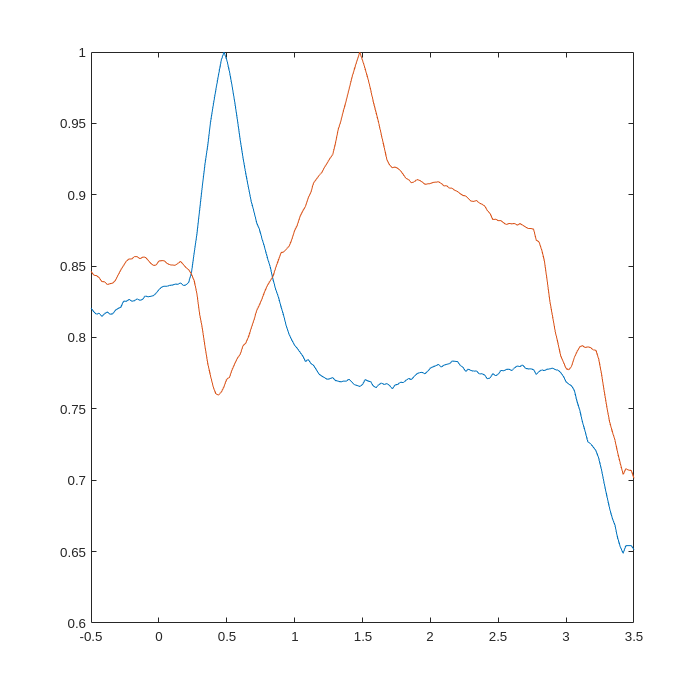

clf, hold off 
plot(tv(wind),CosStates(376-ii,:,4))
hold on
plot(tv(wind),CosStates(426-ii,:,4))
saveas(gcf, "CosSim_l.svg")

### Exp. variance by time

i = 0; f = 3.25; % f = 2.48
lenwin  = sum(tv >= i & tv < f);
Npc = 3;
Eigat = zeros(8,lenwin); %[Stim, Del, Mne, All, Dyn, GLMest, GLMdel]
%Vartott = zeros(1,lenwin);

for e = 1:4 %PCAs
    for t = 1:lenwin
    %    Vartott(t) = sum(diag(squeeze(Covart(:,:,t))));
        for c = 1:Npc
            Eigat(e,t) = Eigat(e,t) + Eigv_list{e}(:,c).'*squeeze(Covart(:,:,t))*Eigv_list{e}(:,c);
        end
    end
end

e = 5;
for t = 1:lenwin %Dyn
    for c = 1:Npc
        Eigat(e,t) = Eigat(e,t) + Eigvt3(:,t,c).'*squeeze(Covart(:,:,t))*Eigvt3(:,t,c);
    end
end

for e = 6:7 %GLM
    if e == 6
        coef = coef0to05;
    else
        coef = coef1to2;
    end
    normcoef = zeros(N,2);
    normcoef(:,1) = coef(:,2) ./ norm(coef(:,2));
    normcoef(:,2) = coef(:,3) ./ norm(coef(:,3));
    for t = 1:lenwin
        for c = 1:2
            Eigat(e,t) = Eigat(e,t) + normcoef(:,c).'*squeeze(Covart(:,:,t))*normcoef(:,c);
        end
    end
end

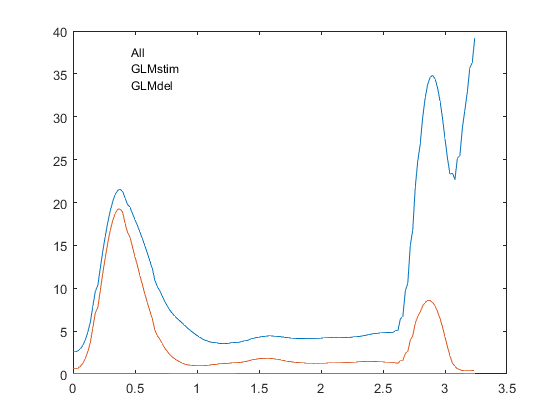

clf, hold off
for c = [4,6,7]
    plot(tv(tv >= i & tv < f), Eigat(c,:)/N) %./Vartott.*100)
    hold on
end
legend("All","GLMstim", "GLMdel","Location","northwest") %"Stim","Del","Mne","Dyn"
saveas(gcf, "VarAx2.svg")

PCA with 2 components

lenwin = 150;
Eigvt2 = zeros(N,lenwin);

for t = 1:lenwin
    [Eigvts, Eiga] = eigs(squeeze(Covart(:,:,t)),2);
    Eigvt2(:,t) = Eigvts(:,2);
end

Cossim2 = zeros(lenwin, lenwin);
for t1 = 1:lenwin
    for t2 = t1:lenwin
       Cossim2(t1,t2) = Eigvt2(:,t1)'*Eigvt2(:,t2) ./ (norm(Eigvt2(:,t1))*norm(Eigvt2(:,t2)));
       Cossim2(t2,t1) = Cossim2(t1,t2);
    end
end

Cossim3 = zeros(lenwin, lenwin);
for t1 = 1:lenwin
    for t2 = t1:lenwin
       Cossim3(t1,t2) = Eigvt(:,t1)'*Eigvt2(:,t2) ./ (norm(Eigvt(:,t1))*norm(Eigvt2(:,t2)));
       Cossim3(t2,t1) = Cossim3(t1,t2);
    end
end

Cossim4 = zeros(lenwin, lenwin);
for t1 = 1:lenwin
    for t2 = t1:lenwin
       Cossim4(t1,t2) = Eigvt2(:,t1)'*Eigvt(:,t2) ./ (norm(Eigvt2(:,t1))*norm(Eigvt(:,t2)));
       Cossim4(t2,t1) = Cossim4(t1,t2);
    end
end

if (Cossim + Cossim2)./2 < (Cossim3 + Cossim4)./2
    Cosssimmin = (Cossim + Cossim2)./2;
else
    Cossimmin = (Cossim3 + Cossim4)./2;
end

DifEiga = zeros(1,lenwin);

for t = 1:lenwin
    [Eigvts, Eiga] = eigs(squeeze(Covart(:,:,t)),2);
    DifEiga(t) = abs(Eiga(1,1)-Eiga(2,2))./sum(diag(Covart(:,:,t)));
end

clf, hold off
plot(tv(tv >= i & tv < f), DifEiga)
title("Difference between explained variance of first 2 PC's")

clf, hold off
figure('Renderer', 'painters', 'Position', [10 10 900 600])
heatmap(abs(Cossim-Cossim2),"CellLabelColor",'none') %max((abs(Cossim) + abs(Cossim2))./2, (abs(Cossim3) + abs(Cossim4))./2)
ticks = [0,repmat(nan,1,24),0.5,repmat(nan,1,24),1,repmat(nan,1,24),1.5,repmat(nan,1,24),2,repmat(nan,1,24),2.5,repmat(nan,1,24)];
ax = gca;
ax.XDisplayLabels = ticks;
ax.YDisplayLabels = ticks;
colormap jet
colorbar
xlabel("t1"), ylabel("t2")
title("Cosine similarity PC1-PC2")

### Explained Variance by axis

PCA

ExpVarPC = zeros(lenwin,lenwin);

for t1 = 1:lenwin
    for t2 = t1:lenwin
        ExpVarPC(t2,t1) = Eigvt(:,t1)'*Covart(:,:,t2)*Eigvt(:,t1);
        ExpVarPC(t1,t2) = Eigvt(:,t2)'*Covart(:,:,t1)*Eigvt(:,t2);
    end
end

clf, hold off
figure('Renderer', 'painters', 'Position', [10 10 900 600])
heatmap(ExpVarPC,"CellLabelColor",'none') 
ticks = [0,repmat(nan,1,24),0.5,repmat(nan,1,24),1,repmat(nan,1,24),1.5,repmat(nan,1,24),2,repmat(nan,1,24),2.5,repmat(nan,1,24)];
ax = gca;
ax.XDisplayLabels = ticks;
ax.YDisplayLabels = ticks;
colormap jet
colorbar
xlabel("t1"), ylabel("t2")
title("Explained variance by PC1 of t1 on t2 CM")

clf, hold off
figure('Renderer', 'painters', 'Position', [10 10 900 600])
heatmap((ExpVarPC - diag(ExpVarPC).*ones(lenwin,lenwin))./diag(ExpVarPC),"CellLabelColor",'none') 
ticks = [0,repmat(nan,1,24),0.5,repmat(nan,1,24),1,repmat(nan,1,24),1.5,repmat(nan,1,24),2,repmat(nan,1,24),2.5,repmat(nan,1,24)];
ax = gca;
ax.XDisplayLabels = ticks;
ax.YDisplayLabels = ticks;
colormap jet
colorbar
xlabel("t1"), ylabel("t2")
title("Explained variance by PC1 of t1 on t2 CM")

GLM

for c = 2:ncoef + 1 %without bias
    normcoef(:,c) = coef31to34(:,c) ./ norm(coef31to34(:,c));
end

ExpVarGLM = zeros(2,lenwin);

for t1 = 1:lenwin
    ExpVarGLM(1,t1) = normcoef(:,2)'*Covart(:,:,t1)*normcoef(:,2);
    ExpVarGLM(2,t1) = normcoef(:,3)'*Covart(:,:,t1)*normcoef(:,3);
end

clf, hold off
plot(tv((tv >= i & tv < f)),ExpVarGLM(1,:),Color=colcoef(1))
hold on
plot(tv((tv >= i & tv < f)),ExpVarGLM(2,:),Color=colcoef(2))
xlabel("t"), ylabel("Explained variance")
legend(["Tac","Aud"])
title("Explained variance by GLM 3.1-3.4")

## Mnemonic PCA

Covarm = zeros(N,N); 
i = tv(401); e = tv(476);% RNN tv(191); e = tv(240); 

Mt = zeros(N,1);
for n = 1:N
    Mt(n) = mean(meanClass{n}(:,tv >= 0 & tv < 3.5),"all","omitnan");
end

for n1 = 1:N
    for n2 = n1:N
       Covarm(n1,n2) = mean((mean(meanClass{n1}(:,tv >= i & tv < e),2,"omitnan")-Mt(n1)).*(mean(meanClass{n2}(:,tv >= i & tv < e),2,"omitnan")-Mt(n2)),"omitnan");
       Covarm(n2,n1) = Covarm(n1,n2);
    end
end


PCA

Nc = 10;
[Eigv, Eiga] = eigs(Covarm,Nc);
Eiga = diag(Eiga);
%Eigv_list{3} = Eigv;

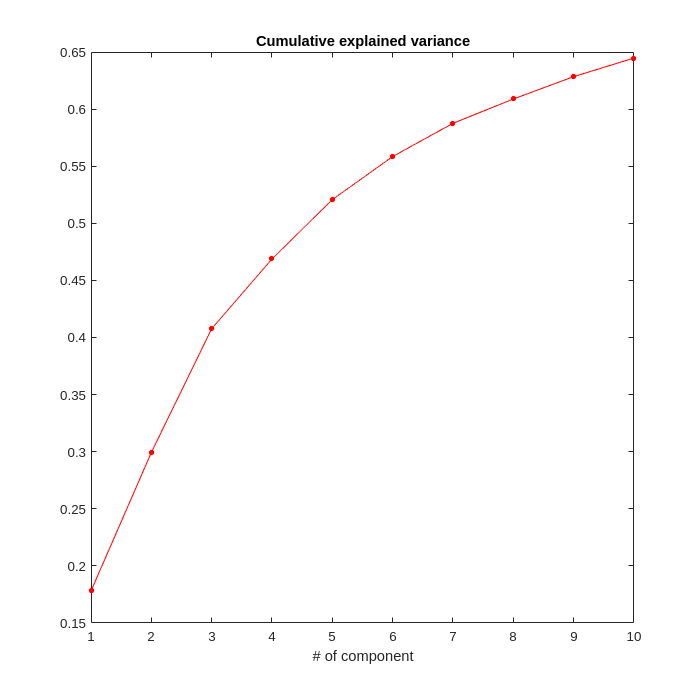


clf, hold off
plot(1:Nc,cumsum(abs(Eiga))./sum(diag(Covar)),"Color","r","Marker",".",MarkerSize=12)
xlim([1,Nc]), title("Cumulative explained variance"), xlabel("# of component")

### MPCA Noise TODO

Covar noise

Covarn = zeros(N,N,100); 
wb = waitbar(0);

for p = 1:100
    waitbar(p/100, wb, strcat(num2str(p),"%"))
    for n1 = 1:N
        for n2 = n1:N
           cv = 0;
           for e1 = randperm(length(Fr{n1}(:,1)),10)%length(Fr{n1}(:,1))
               for e2 = randperm(length(Fr{n2}(:,1)),10)%length(Fr{n2}(:,1))
                cv = cv + mean((Frn{n1}(e1,tv >= i & tv < e)).*(Frn{n2}(e2,tv >= i & tv < e)),"omitnan")/(length(Fr{n1}(:,1))*length(Fr{n2}(:,1))); 
               end
           end
           Covarn(n1,n2,p) = cv;
           Covarn(n2,n1,p) = Covar(n1,n2);
        end
    end
end

PCA

Eigaps = zeros(100,Nc);
Vartotp = zeros(100,1);

for p = 1:100
    [~, Eigap] = eigs(squeeze(Covarn(:,:,p)),Nc);
    Eigaps(p,:) = diag(Eigap);
    Vartotp(p) = sum(diag(squeeze(Covarn(:,:,p))));
end

Ploting

clf, hold off
y = mean(abs(Eigaps)./Vartotp);
s = std(abs(Eigaps)./Vartotp);
fill([1:Nc, fliplr(1:Nc)], [y + 2*s, fliplr(y - 2*s)], 'g', Facealpha = 0.5, edgecolor="none")
hold on
plot(1:Nc,y,"Color","k","Marker",".",MarkerSize=12)
plot(1:Nc,abs(Eiga)./sum(diag(Covar)),"Color","r","Marker",".",MarkerSize=12)
xlim([1,Nc]), xlabel("# of component")
%saveas(gcf, "VarPCAest.svg")

### Proyection in coefficients

nPc = 6;
proyecPC = zeros(nPc, C + 2, lentv);

for c = 1:nPc    
    for t = 1:lentv
        for s = 1:C
            proyecPC(c, s, t) = meanClassvec(:, s, t)'*Eigv(:,c);
        end
        proyecPC(c, end - 1, t) = mean(meanClassvec(:, 3:6, t), 2, "omitnan")'*Eigv(:,c); %All Aud
        proyecPC(c, end, t) = mean(meanClassvec(:, 7:end, t), 2, "omitnan")'*Eigv(:,c); %All Tac
    end
end

Ploting

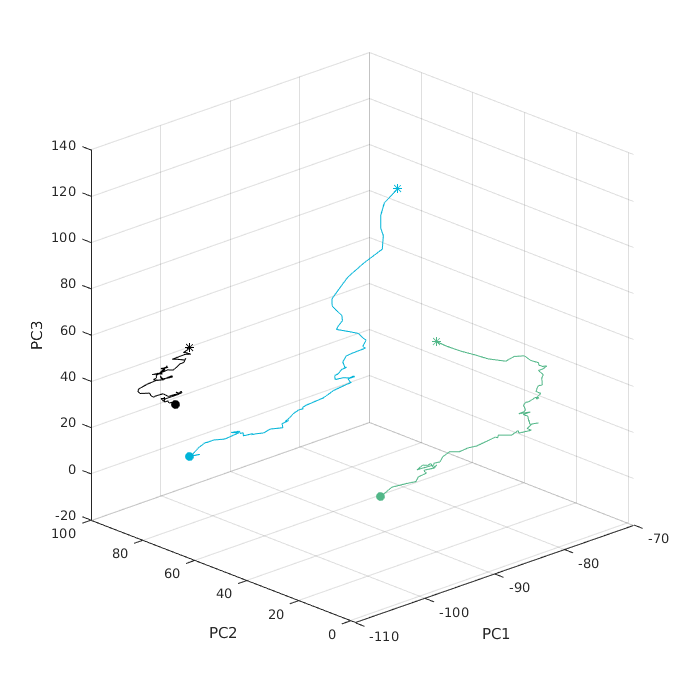

%i = tv(413); f = tv(471);
wind = tv >= i & tv <= e;

clf, hold off

plot3(squeeze(proyecPC(1,1,wind)),squeeze(proyecPC(2,1,wind)),squeeze(proyecPC(3,1,wind)),"color","k")
hold on
plot3(squeeze(proyecPC(1,end - 1,wind)),squeeze(proyecPC(2,end - 1,wind)),squeeze(proyecPC(3,end - 1,wind)),"color",colcoef(2))
plot3(squeeze(proyecPC(1,end,wind)),squeeze(proyecPC(2,end,wind)),squeeze(proyecPC(3,end,wind)),"color",colcoef(1))
xlabel("PC1"), ylabel("PC2"), zlabel("PC3")

scatter3([proyecPC(1,1,tv == i), proyecPC(1,end - 1,tv == i), proyecPC(1,end,tv == i)], ...
    [proyecPC(2,1,tv == i), proyecPC(2,end - 1,tv == i), proyecPC(2,end,tv == i)], ...
    [proyecPC(3,1,tv == i), proyecPC(3,end-1,tv == i), proyecPC(3,end,tv == i)], [], rgb, Marker="*")
scatter3([proyecPC(1,1,tv == e), proyecPC(1,end - 1,tv == e), proyecPC(1,end,tv == e)], ...
    [proyecPC(2,1,tv == e), proyecPC(2,end - 1,tv == e), proyecPC(2,end,tv == e)], ...
    [proyecPC(3,1,tv == e), proyecPC(3,end-1,tv == e), proyecPC(3,end,tv == e)], [], rgb, Marker="o",MarkerFaceColor="flat")
grid on

view([-43.6 21.0])

saveas(gcf, "MPCA.svg")

Multilinear

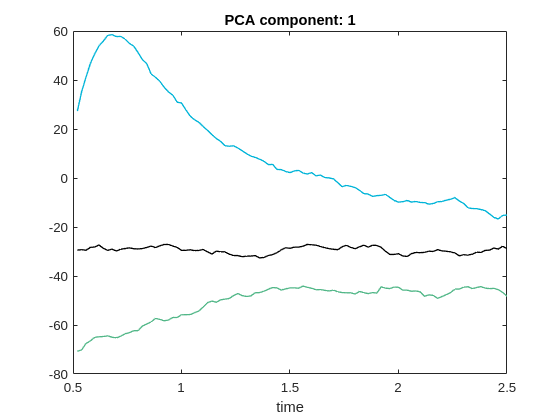

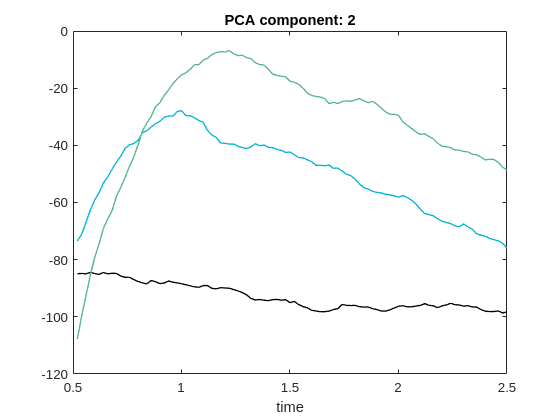

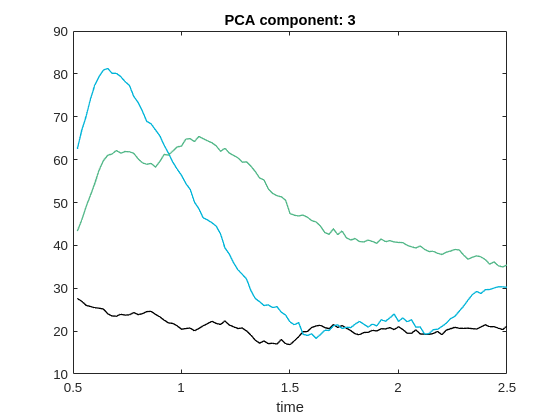

for p = 1
    clf, hold off
    plot(tv(wind),squeeze(proyecPC(p,1,wind)),"color","k","LineWidth",1)
    hold on
    plot(tv(wind),squeeze(proyecPC(p,end - 1,wind)),"color",colcoef(2),"LineWidth",1)
    plot(tv(wind),squeeze(proyecPC(p,end,wind)),"color",colcoef(1),"LineWidth",1)
    
    xlabel("time")
    title(strcat("PCA component: ", num2str(p)))
end

### End

function Data = readPsico(file)
    opts = delimitedTextImportOptions("NumVariables", 31);
    opts.DataLines = [2, Inf];
    opts.Delimiter = ",";
    opts.VariableNames = ["Trial", "Class", "SelectedButton", "CorrectButton", "Hits", "AmpStim1", "FreqStim1", "AudStim1", "AmpStim2", "FreqStim2", "AudStim2", "AmpStim3", "FreqStim3", "AudStim3", "RelKD", "RelKU", "RelMov", "Luz", "TRW", "Set", "pd", "kd", "o1", "f1", "o2", "f2", "o3", "f3", "pu", "ku", "pb"];
    opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
    opts.ExtraColumnsRule = "ignore";
    opts.EmptyLineRule = "read";
    
    Data = readtable(file, opts);
end

function Fr = freq(D,pas,ven, mini, maxi)
    [xd, ~] = size(D);
    num = fix(ven/pas);
    tv = mini:pas:maxi;
    D = fix((D-mini)/pas)+1;
    Fr = zeros(xd,length(tv));
    for ens = 1 : xd
        for x = 1 : (length(tv)-num)
            B = (D(ens,:)>x-num & D(ens,:)<=x);
            suma = sum(B(:));
            Fr(ens,x+num) = suma/ven;
        end
    end
end

function Fr = convo(D,pas,ven,mini,maxi,tipo)
    clf
    [xd, ~] = size(D);
    tv = mini:pas:maxi;
    Fr = zeros(xd,length(tv));
    if tipo==1
        con = @(c) sum(exp(-c.^2./(2*ven^2)),2,'omitnan')./(ven*sqrt(pi*2));
    elseif tipo==2
        con = @(c) 2*sum((c>=0).*exp(-c.^2./(2*ven^2)),2,'omitnan')./(ven*sqrt(pi*2));
    end
    for row =1:xd
        C = bsxfun(@minus,tv',D(row,:));
        Fr(row,:) = con(C);    
    end
end
